## Add Model and Algorithm Libraries to Matlab's Path

addpath('C:\Users\mrmehta\Documents\GitHub\PrognosticsModelLibrary\MATLAB')
addpath('C:\Users\mrmehta\Documents\GitHub\PrognosticsAlgorithmLibrary\MATLAB')

## Showcasing ISC

The model is hard coded for the C-rate, minimum ISC current is fixed to 0A, and the only parameter that is being varied or changed in the prognostics is the time at which the short circuit is applied.

clf;
oneC = 2.021; %Default value
crate = 5;
% disp(crate);
loadval = oneC.*crate;
% loads = [0;5*60;loadval;3600];
% 
% simresults = testBatteryModel(loads);
faulttimes = linspace(5,60,10);
nfaults = length(faulttimes);
dischargetime = nan.*ones([nfaults,3600]);
dischargevoltage = nan.*ones([nfaults,3600]);
dischargetemperature = nan.*ones([nfaults,3600]);
c = jet(nfaults);
c = flipud(c);
figure(1)
clf;
hold on
figure(2)
clf;
hold on
for i=1:nfaults
    loads = [0;faulttimes(i)*60;loadval;3600];
    simresults = testBatteryModel(loads);    
    dischargetime(i,1:length(simresults.time)) = simresults.time;
    dischargevoltage(i,1:length(simresults.voltage)) = simresults.voltage;
    figure(1)
    plot(dischargetime(i,:), dischargevoltage(i,:), "Color",c(i,:))
    dischargetemperature(i,1:length(simresults.temperature)) = simresults.temperature;
    figure(2)
    plot(dischargetime(i,:), dischargetemperature(i,:), "Color",c(i,:))    
    
end

Maximum current: 0


Maximum current: 0


Maximum current: 0


Maximum current: 0


Maximum current: 0


Maximum current: 0


Maximum current: 0


Maximum current: 0


Maximum current: 0


Maximum current: 0


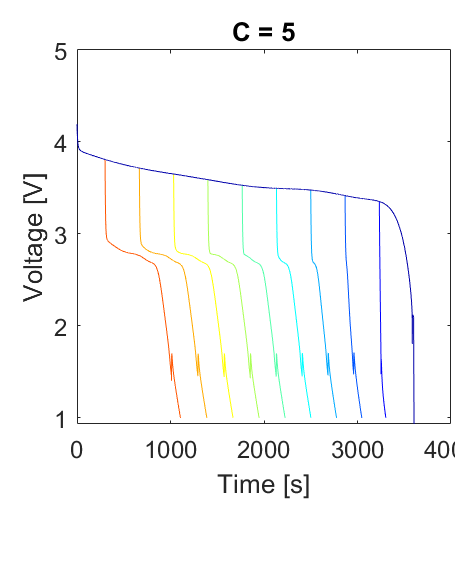

figure(1)
xlabel('Time [s]');
ylabel('Voltage [V]');
axis square
box on
ax = gca;
ax.Color = 'none';
ax.Position = [0.169444444444445 0.175000069936117 0.822222152286105 0.822222152286105];
fg = gcf;
fg.PaperType = "<custom>";
fg.PaperSize = [3 3];
fg.Renderer = 'painters';
fg.OuterPosition = [643 325 303.6 381];
ax.FontSize = 12;
title(['C = ',num2str(crate)])

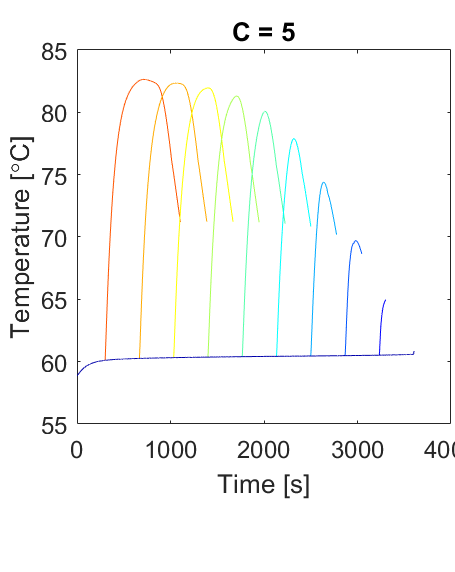

figure(2)
xlabel('Time [s]');
ylabel('Temperature [\circC]');
axis square
box on
ax = gca;
% ax.YLim = [58,64];
ax.Color = 'none';
ax.Position = [0.169444444444445 0.175000069936117 0.822222152286105 0.822222152286105];
fg = gcf;
fg.PaperType = "<custom>";
fg.PaperSize = [3 3];
fg.Renderer = 'painters';
fg.OuterPosition = [643 325 303.6 381];
ax.FontSize = 12;
title(['C = ',num2str(crate)])

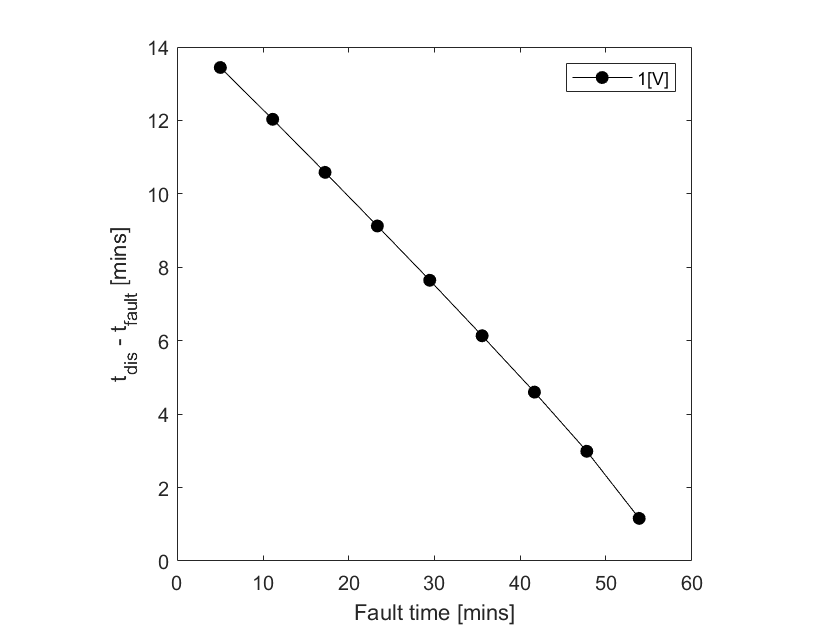

figure(10)
hold on
tdiff = max(dischargetime,[],2) - faulttimes'.*60;
plot(faulttimes(1:end-1),tdiff(1:end-1)./60,'o-','Color','k','MarkerFaceColor','k','DisplayName',[num2str(simresults.VEOD) '[V]'])
xlabel('Fault time [mins]')
ylabel('t_{dis} - t_{fault} [mins]')
legend show
box on 
axis square

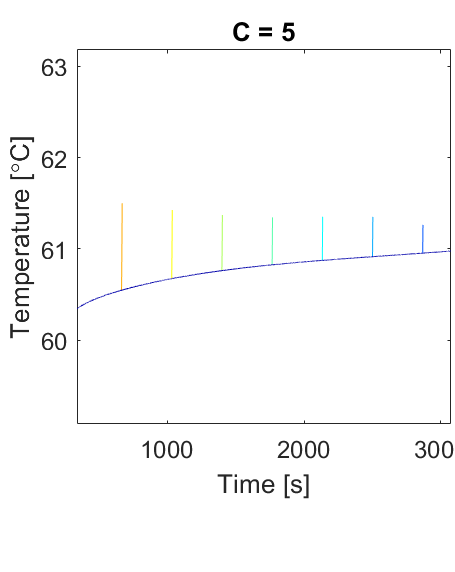

figure(2)
xlabel('Time [s]');
ylabel('Temperature [\circC]');
axis square
box on
ax = gca;
ax.YLim = [58,64];
ax.Color = 'none';
ax.Position = [0.169444444444445 0.175000069936117 0.822222152286105 0.822222152286105];
fg = gcf;
fg.PaperType = "<custom>";
fg.PaperSize = [3 3];
fg.Renderer = 'painters';
fg.OuterPosition = [643 325 303.6 381];
ax.FontSize = 12;
title(['C = ',num2str(crate)])

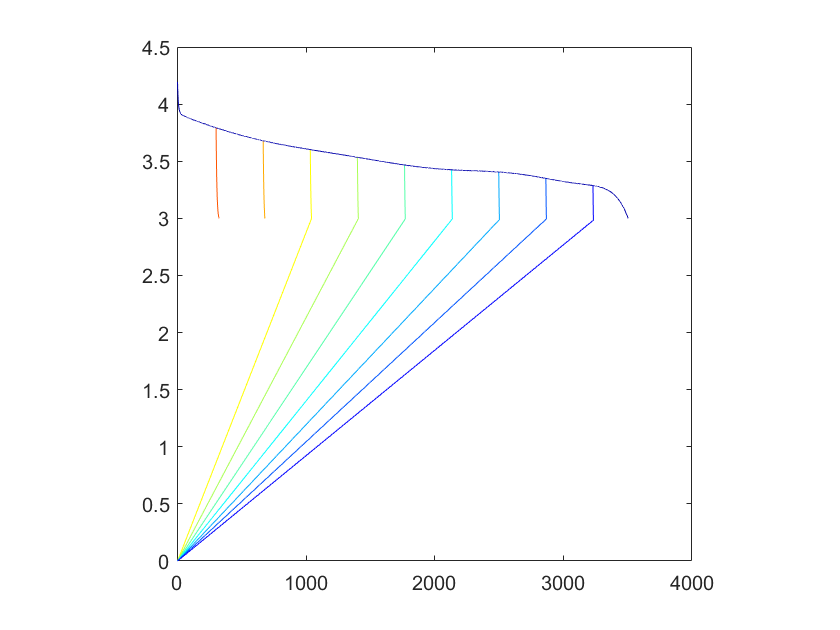

c = jet(nfaults);
c = flipud(c);
figure
hold on
for i=1:nfaults
    plot(dischargetime(i,:), dischargevoltage(i,:), "Color",c(i,:))
end
hold off
box on 
axis square

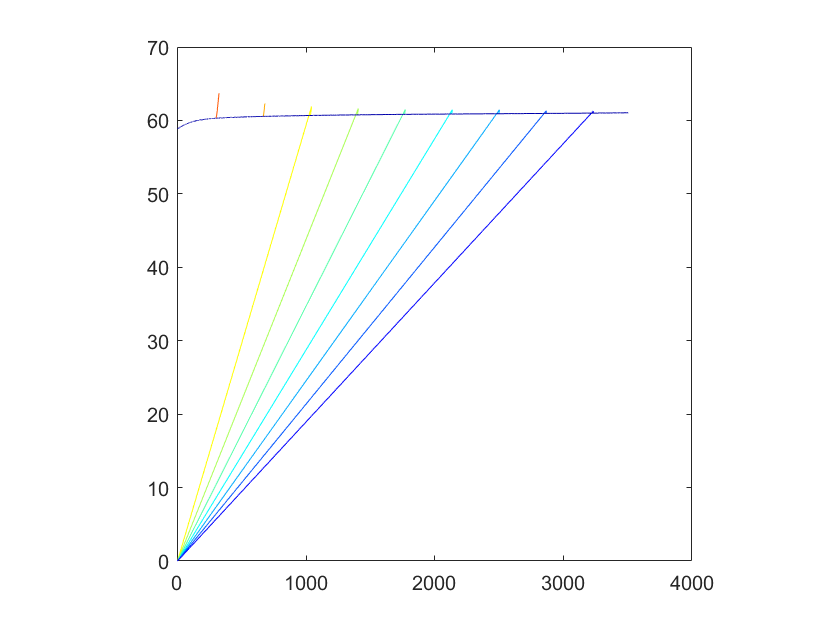



figure
hold on
for i=1:nfaults
    plot(dischargetime(i,:), dischargetemperature(i,:), "Color",c(i,:))        
end
hold off
box on 
axis square

## 1C simulation

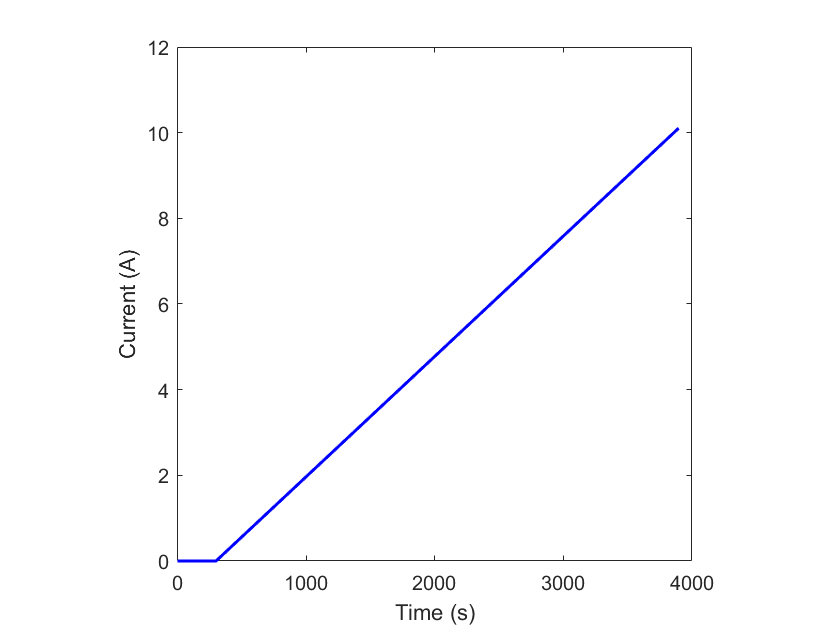

clf;

oneC = 2.021; %Default value
crate = 5;
% disp(crate);
loadval = oneC.*crate;
loads = [0;5*60;loadval;3600];
% loads = [4.2; 100*36];
horizon = 3600;
numSamples = 100;
simresults = testPrognoser(loads,horizon,numSamples);

Maximum current: 0


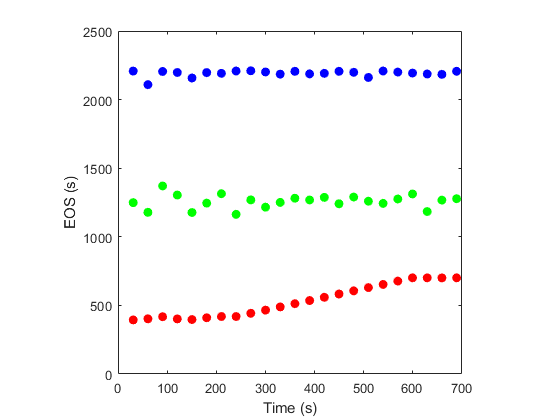

figure
plot(simresults.time,simresults.minEOD,'o','Color','red','DisplayName','Predicted EOD Min','MarkerFaceColor','red');
hold on
plot(simresults.time,simresults.maxEOD,'o','Color','blue','DisplayName','Predicted EOD Max','MarkerFaceColor','blue');
plot(simresults.time,simresults.meanEOD,'o','Color','green','DisplayName','Predicted EOD Mean','MarkerFaceColor','green');
hold off
xlabel('Time (s)');
ylabel('EOS (s)');
axis square
box on
ax = gca;
ax.Color = 'None';

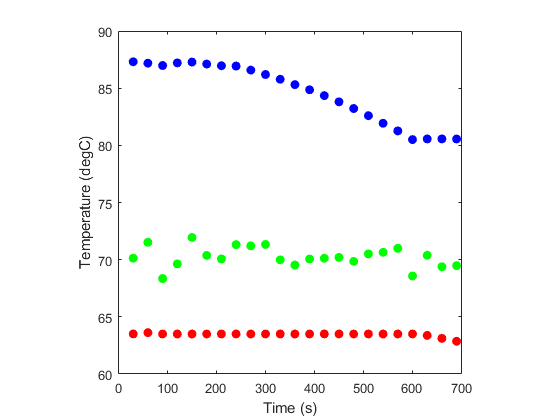


figure
plot(simresults.time,simresults.minTemp,'o','Color','red','DisplayName','Predicted T Min','MarkerFaceColor','red');
hold on
plot(simresults.time,simresults.maxTemp,'o','Color','blue','DisplayName','Predicted T Max','MarkerFaceColor','blue');
plot(simresults.time,simresults.meanTemp,'o','Color','green','DisplayName','Predicted T Mean','MarkerFaceColor','green');
hold off
xlabel('Time (s)');
ylabel('Temperature (degC)');
axis square
box on
ax = gca;
ax.Color = 'None';

figure
plot(simresults.time,simresults.voltage)
xlabel('Time (s)');
ylabel('Voltage (V)');
axis square


## 2C simulation

Maximum current: 2.021


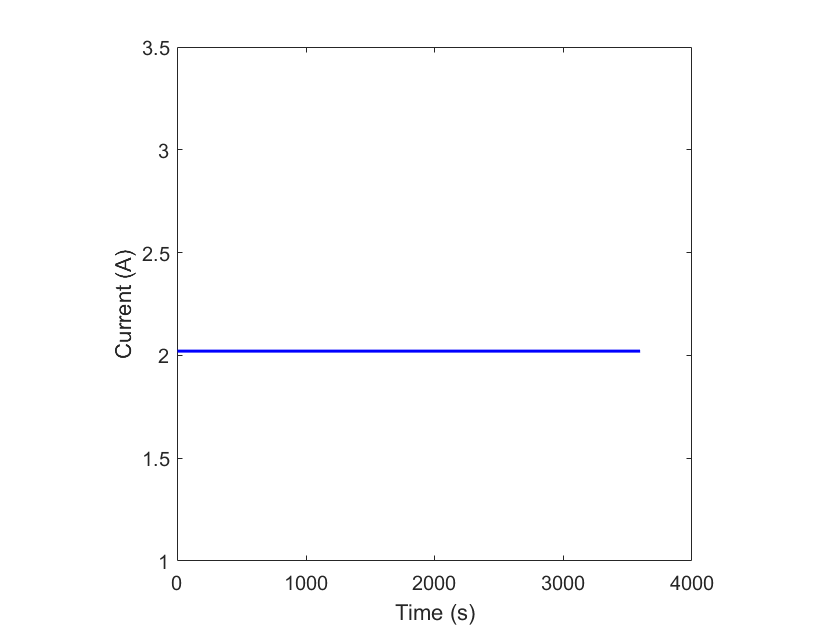

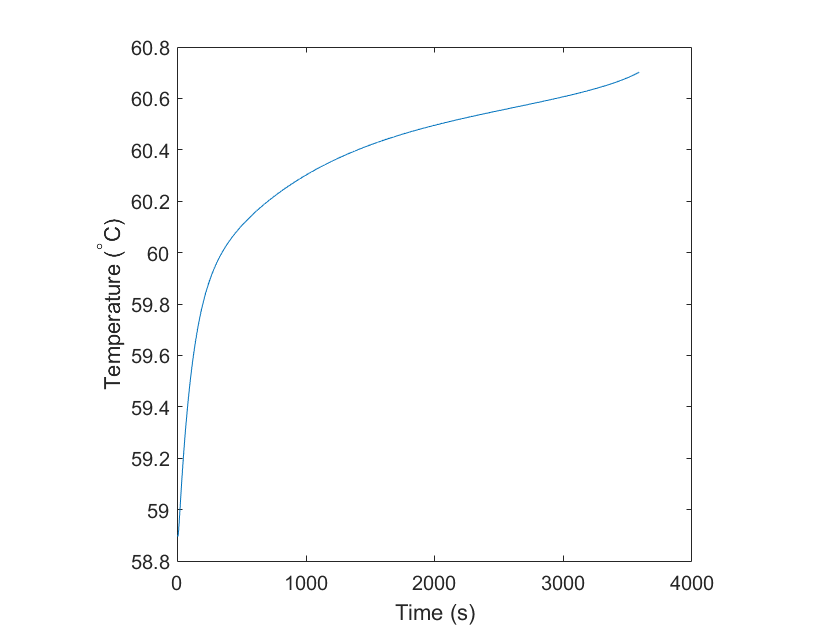

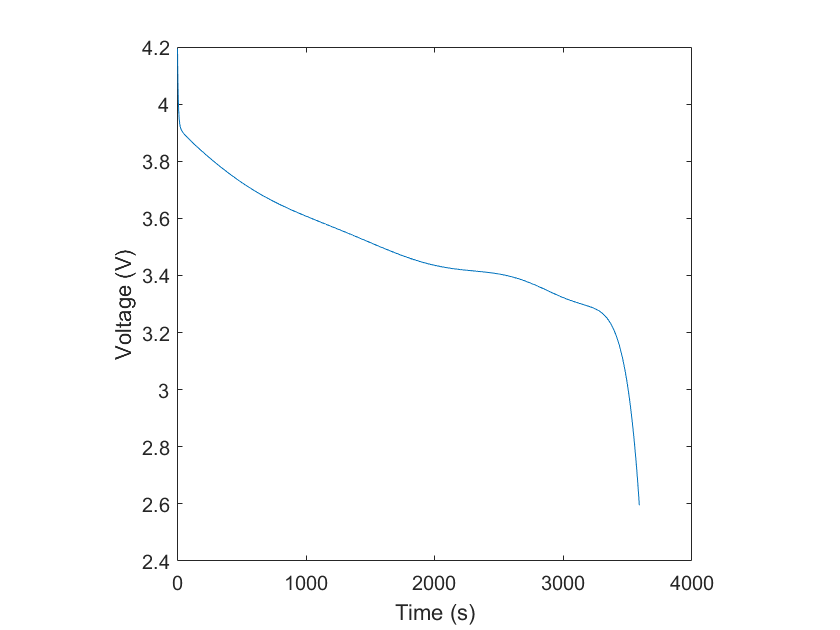

clear all
close all
clf;
oneC = 2.021; %Default value
crate = 1;
loadval = oneC.*crate;
loads = [loadval;3600];
% loads = [4.2; 100*36];
horizon = 5000;
numSamples = 100;
simresults = testPrognoser(loads,horizon,numSamples);

figure;
plot(simresults.time,simresults.voltage)
figure
plot(simresults.time,simresults.minTemp,'o','Color','red','DisplayName','Predicted T Min','MarkerFaceColor','red');
hold on
plot(simresults.time,simresults.maxTemp,'o','Color','blue','DisplayName','Predicted EOD Max','MarkerFaceColor','blue');
plot(simresults.time,simresults.meanTemp,'o','Color','green','DisplayName','Predicted EOD Mean','MarkerFaceColor','green');
hold off
xlabel('Time (s)');
ylabel('Temperature (degC)');
axis square
box on
ax = gca;
ax.Color = 'None';

## Trying to Match Chetan's Data

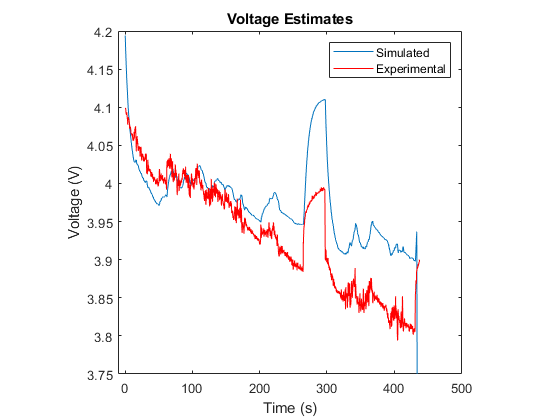


battery = Battery.Create;
oneC = 2.1; %Default value
trueEOD = 433.02;
trueEODinHr = trueEOD./3600;
loadval = oneC./trueEODinHr;   
% loads = [1.0327;12.7800;0.8917;0.2400;0.8917;3.1800;1.0290;0.1800;1.0290;15.0000;1.2000;0.2400;1.2000;1.8000;1.1284;0.1800;1.1284;17.8200;1.0397;0.1800;1.0397;10.0200;0.7242;0.1800;0.7242;7.2000;0.9028;0.1800;0.9028;133.2000;0.8173;0.2400;0.8173;22.5600;0.9602;0.2400;0.9602;39.1800;0.0469;0.1800;0.0469;32.2200;1.0116;0.1800;1.0116;133.8000;0.5110;0.2400;0.3651;0.1800;0.3186;0.1800;0.2685;0.2400;0.1870;0.1800;0.1545;0.1800;0.1571;0.2400;0.1602;0.1800;0.1589;0.1800;0.1585;0.2400];
loads = [1.60;0.18;1.53;0.24;1.52;0.18;1.49;0.18;1.49;0.24;1.52;0.18;1.54;0.18;1.54;0.24;1.56;0.18;1.53;0.18;1.48;0.24;1.44;0.18;1.42;0.18;1.46;0.24;1.49;0.18;1.52;0.18;1.56;0.24;1.57;0.18;1.62;0.18;1.61;0.24;1.51;0.18;1.48;0.18;1.46;0.24;1.44;0.18;1.44;0.18;1.43;0.24;1.40;0.18;1.39;0.18;1.39;0.24;1.39;0.18;1.45;0.18;1.50;0.24;1.57;0.18;1.52;0.18;1.49;0.24;1.47;0.18;1.48;0.18;1.49;0.24;1.48;0.18;1.45;0.18;1.49;0.24;1.52;0.18;1.54;0.18;1.56;0.24;1.56;0.18;1.55;0.18;1.55;0.24;1.55;0.18;1.51;0.18;1.54;0.24;1.54;0.18;1.55;0.18;1.55;0.24;1.46;0.18;1.46;0.18;1.57;0.24;1.52;0.18;1.58;0.18;1.62;0.24;1.58;0.18;1.52;0.18;1.57;0.24;1.59;0.18;1.55;0.18;1.45;0.24;1.37;0.18;1.33;0.18;1.39;0.24;1.48;0.18;1.41;0.18;1.32;0.24;1.21;0.18;1.25;0.18;1.27;0.24;1.19;0.18;1.15;0.18;1.13;0.24;1.18;0.18;1.24;0.18;1.32;0.24;1.42;0.18;1.50;0.18;1.73;0.24;1.53;0.18;1.56;0.18;1.53;0.24;1.42;0.18;1.33;0.18;1.33;0.24;1.36;0.18;1.37;0.18;1.38;0.24;1.43;0.18;1.46;0.18;1.47;0.24;1.54;0.18;1.58;0.18;1.59;0.24;1.59;0.18;1.57;0.18;1.55;0.24;1.50;0.18;1.50;0.18;1.49;0.24;1.47;0.18;1.49;0.18;1.47;0.24;1.44;0.18;1.46;0.18;1.52;0.24;1.64;0.18;1.63;0.18;1.58;0.24;1.49;0.18;1.44;0.18;1.40;0.24;1.40;0.18;1.44;0.18;1.43;0.24;1.52;0.18;1.54;0.18;1.64;0.24;1.66;0.18;1.60;0.18;1.58;0.24;1.57;0.18;1.58;0.18;1.52;0.24;1.48;0.18;1.46;0.18;1.47;0.24;1.46;0.18;1.53;0.18;1.56;0.24;1.63;0.18;1.63;0.18;1.62;0.24;1.60;0.18;1.57;0.18;1.48;0.24;1.52;0.18;1.58;0.18;1.60;0.24;1.58;0.18;1.58;0.18;1.57;0.24;1.49;0.18;1.49;0.18;1.49;0.24;1.47;0.18;1.40;0.18;1.36;0.24;1.35;0.18;1.44;0.18;1.53;0.24;1.43;0.18;1.35;0.18;1.37;0.24;1.63;0.18;1.78;0.18;1.83;0.24;1.78;0.18;1.82;0.18;1.84;0.24;1.83;0.18;1.77;0.18;1.74;0.24;1.52;0.18;1.40;0.18;1.45;0.24;1.55;0.18;1.54;0.18;1.53;0.24;1.58;0.18;1.62;0.18;1.68;0.24;1.61;0.18;1.63;0.18;1.63;0.24;1.61;0.18;1.63;0.18;1.64;0.24;1.64;0.18;1.64;0.18;1.62;0.24;1.61;0.18;1.67;0.18;1.66;0.24;1.65;0.18;1.60;0.18;1.74;0.24;1.68;0.18;1.63;0.18;1.64;0.24;1.65;0.18;1.67;0.18;1.67;0.24;1.63;0.18;1.72;0.18;1.75;0.24;1.70;0.18;1.64;0.18;1.67;0.24;1.65;0.18;1.67;0.18;1.70;0.24;1.74;0.18;1.73;0.18;1.74;0.24;1.70;0.18;1.79;0.18;1.69;0.24;1.69;0.18;1.64;0.18;1.63;0.24;1.66;0.18;1.74;0.18;1.71;0.24;1.67;0.18;1.73;0.18;1.74;0.24;1.68;0.18;1.71;0.18;1.73;0.24;1.73;0.18;1.71;0.18;1.77;0.24;1.73;0.18;1.76;0.18;1.77;0.24;1.73;0.18;1.75;0.18;1.66;0.24;1.74;0.18;1.59;0.18;1.68;0.24;1.62;0.18;1.62;0.18;1.61;0.24;1.68;0.18;1.68;0.18;1.67;0.24;1.71;0.18;1.75;0.18;1.75;0.24;1.72;0.18;1.66;0.18;1.73;0.24;1.61;0.18;1.64;0.18;1.66;0.24;1.66;0.18;1.55;0.18;1.37;0.24;1.30;0.18;1.33;0.18;1.32;0.24;1.50;0.18;1.58;0.18;1.57;0.24;1.58;0.18;1.58;0.18;1.57;0.24;1.50;0.18;1.48;0.18;1.46;0.24;1.43;0.18;1.41;0.18;1.42;0.24;1.57;0.18;1.54;0.18;1.51;0.24;1.49;0.18;1.47;0.18;1.52;0.24;1.49;0.18;1.46;0.18;1.47;0.24;1.44;0.18;1.52;0.18;1.57;0.24;1.53;0.18;1.52;0.18;1.51;0.24;1.56;0.18;1.64;0.18;1.54;0.24;1.48;0.18;1.50;0.18;1.50;0.24;1.46;0.18;1.52;0.18;1.52;0.24;1.50;0.18;1.44;0.18;1.43;0.24;1.45;0.18;1.46;0.18;1.59;0.24;1.55;0.18;1.48;0.18;1.53;0.24;1.57;0.18;1.55;0.18;1.58;0.24;1.56;0.18;1.65;0.18;1.71;0.24;1.56;0.18;1.17;0.18;1.01;0.24;1.01;0.18;0.96;0.18;1.03;0.24;1.11;0.18;0.93;0.18;0.94;0.24;1.00;0.18;1.02;0.18;1.10;0.24;1.13;0.18;1.06;0.18;1.10;0.24;0.98;0.18;0.97;0.18;1.00;0.24;0.93;0.18;1.20;0.18;1.19;0.24;1.08;0.18;1.01;0.18;1.21;0.24;1.21;0.18;1.24;0.18;1.16;0.24;0.85;0.18;0.81;0.18;1.08;0.24;1.03;0.18;1.02;0.18;1.13;0.24;1.17;0.18;1.18;0.18;0.95;0.24;1.05;0.18;1.14;0.18;1.40;0.24;1.44;0.18;1.20;0.18;1.10;0.24;1.07;0.18;1.03;0.18;1.07;0.24;1.23;0.18;1.39;0.18;1.49;0.24;1.55;0.18;1.55;0.18;1.47;0.24;1.38;0.18;1.47;0.18;1.35;0.24;1.41;0.18;1.46;0.18;1.50;0.24;1.46;0.18;1.43;0.18;1.42;0.24;1.39;0.18;1.32;0.18;1.26;0.24;1.18;0.18;1.03;0.18;1.05;0.24;1.15;0.18;1.26;0.18;1.20;0.24;1.37;0.18;1.34;0.18;1.31;0.24;1.28;0.18;1.28;0.18;1.40;0.24;1.39;0.18;1.56;0.18;1.79;0.24;1.86;0.18;1.75;0.18;1.61;0.24;1.50;0.18;1.47;0.18;1.52;0.24;1.53;0.18;1.42;0.18;1.39;0.24;1.45;0.18;1.42;0.18;1.29;0.24;1.19;0.18;1.21;0.18;1.64;0.24;1.60;0.18;1.46;0.18;1.38;0.24;1.42;0.18;1.44;0.18;1.33;0.24;1.37;0.18;1.45;0.18;1.46;0.24;1.47;0.18;1.43;0.18;1.43;0.24;1.32;0.18;1.39;0.18;1.35;0.24;1.33;0.18;1.31;0.18;1.37;0.24;1.35;0.18;1.27;0.18;1.24;0.24;1.30;0.18;1.32;0.18;1.27;0.24;1.18;0.18;1.17;0.18;1.11;0.24;1.10;0.18;1.04;0.18;1.04;0.24;1.08;0.18;1.04;0.18;1.06;0.24;1.18;0.18;1.20;0.18;1.09;0.24;1.10;0.18;1.13;0.18;1.10;0.24;1.07;0.18;1.16;0.18;1.20;0.24;1.25;0.18;1.13;0.18;1.17;0.24;1.32;0.18;1.19;0.18;1.09;0.24;0.95;0.18;1.20;0.18;1.22;0.24;1.21;0.18;1.37;0.18;1.32;0.24;1.34;0.18;1.16;0.18;1.25;0.24;1.26;0.18;1.27;0.18;1.25;0.24;1.17;0.18;1.23;0.18;1.38;0.24;1.34;0.18;1.33;0.18;1.43;0.24;1.47;0.18;1.35;0.18;1.23;0.24;1.11;0.18;1.19;0.18;1.24;0.24;1.19;0.18;1.37;0.18;1.63;0.24;1.35;0.18;1.38;0.18;1.67;0.24;1.65;0.18;1.59;0.18;1.40;0.24;1.42;0.18;1.52;0.18;1.61;0.24;1.38;0.18;1.28;0.18;1.26;0.24;1.31;0.18;1.33;0.18;1.21;0.24;1.12;0.18;1.03;0.18;0.99;0.24;1.05;0.18;1.12;0.18;1.21;0.24;1.25;0.18;1.17;0.18;1.14;0.24;1.19;0.18;1.27;0.18;1.32;0.24;1.33;0.18;1.34;0.18;1.34;0.24;1.31;0.18;1.28;0.18;1.25;0.24;1.24;0.18;1.25;0.18;1.41;0.24;1.37;0.18;1.27;0.18;1.13;0.24;1.07;0.18;1.15;0.18;1.28;0.24;1.22;0.18;1.24;0.18;1.15;0.24;1.08;0.18;1.04;0.18;1.00;0.24;0.80;0.18;0.90;0.18;1.10;0.24;1.11;0.18;1.06;0.18;0.85;0.24;0.81;0.18;0.95;0.18;1.28;0.24;1.10;0.18;0.94;0.18;0.76;0.24;0.73;0.18;0.83;0.18;1.01;0.24;1.03;0.18;0.92;0.18;0.92;0.24;1.09;0.18;1.08;0.18;1.01;0.24;0.92;0.18;1.03;0.18;1.11;0.24;1.08;0.18;1.06;0.18;1.02;0.24;0.92;0.18;1.07;0.18;1.17;0.24;1.23;0.18;1.24;0.18;1.21;0.24;1.21;0.18;1.24;0.18;1.28;0.24;1.29;0.18;1.28;0.18;1.36;0.24;1.40;0.18;1.31;0.18;1.18;0.24;1.13;0.18;1.08;0.18;1.14;0.24;1.23;0.18;1.25;0.18;1.28;0.24;1.31;0.18;1.32;0.18;1.33;0.24;1.27;0.18;1.24;0.18;1.28;0.24;1.35;0.18;1.37;0.18;1.34;0.24;1.39;0.18;1.40;0.18;1.42;0.24;1.41;0.18;1.42;0.18;1.53;0.24;1.50;0.18;1.48;0.18;1.49;0.24;1.55;0.18;1.44;0.18;1.33;0.24;1.42;0.18;1.35;0.18;1.30;0.24;1.31;0.18;1.26;0.18;1.41;0.24;1.60;0.18;1.60;0.18;1.48;0.24;1.53;0.18;1.47;0.18;1.37;0.24;1.28;0.18;1.18;0.18;1.28;0.24;1.28;0.18;1.38;0.18;1.36;0.24;1.40;0.18;1.39;0.18;1.37;0.24;1.41;0.18;1.34;0.18;1.40;0.24;1.36;0.18;1.17;0.18;1.23;0.24;1.25;0.18;1.16;0.18;1.27;0.24;1.31;0.18;1.40;0.18;1.39;0.24;1.47;0.18;1.52;0.18;1.60;0.24;1.29;0.18;1.18;0.18;1.14;0.24;1.18;0.18;1.19;0.18;1.31;0.24;1.49;0.18;1.31;0.18;1.23;0.24;1.16;0.18;1.03;0.18;0.85;0.24;1.17;0.18;1.34;0.18;1.35;0.24;1.28;0.18;1.05;0.18;1.20;0.24;1.29;0.18;1.32;0.18;1.41;0.24;1.36;0.18;1.28;0.18;1.30;0.24;1.15;0.18;1.22;0.18;1.19;0.24;1.11;0.18;1.09;0.18;1.21;0.24;0.99;0.18;1.01;0.18;1.03;0.24;1.00;0.18;1.28;0.18;1.17;0.24;1.02;0.18;0.98;0.18;1.15;0.24;1.22;0.18;1.26;0.18;1.27;0.24;1.29;0.18;1.10;0.18;1.08;0.24;1.11;0.18;1.00;0.18;1.00;0.24;1.13;0.18;1.14;0.18;1.21;0.24;1.21;0.18;1.21;0.18;1.10;0.24;1.13;0.18;1.21;0.18;1.10;0.24;1.11;0.18;1.29;0.18;1.34;0.24;1.39;0.18;1.37;0.18;1.26;0.24;1.22;0.18;1.16;0.18;1.20;0.24;1.19;0.18;1.18;0.18;1.17;0.24;1.13;0.18;1.23;0.18;1.27;0.24;1.28;0.18;1.39;0.18;1.31;0.24;1.23;0.18;1.13;0.18;1.19;0.24;1.16;0.18;1.27;0.18;1.19;0.24;1.21;0.18;1.24;0.18;1.24;0.24;1.22;0.18;1.39;0.18;1.45;0.24;1.37;0.18;1.30;0.18;1.23;0.24;1.21;0.18;1.20;0.18;1.19;0.24;1.18;0.18;1.22;0.18;1.28;0.24;1.30;0.18;1.29;0.18;1.33;0.24;1.33;0.18;1.38;0.18;1.37;0.24;1.37;0.18;1.37;0.18;1.35;0.24;1.42;0.18;1.47;0.18;1.47;0.24;1.49;0.18;1.45;0.18;1.37;0.24;1.09;0.18;0.97;0.18;0.95;0.24;0.98;0.18;1.21;0.18;1.19;0.24;1.11;0.18;1.17;0.18;1.25;0.24;1.22;0.18;1.25;0.18;1.23;0.24;1.17;0.18;1.12;0.18;1.06;0.24;1.13;0.18;1.26;0.18;1.26;0.24;1.19;0.18;1.15;0.18;1.17;0.24;1.25;0.18;1.32;0.18;1.14;0.24;1.28;0.18;1.27;0.18;1.27;0.24;1.19;0.18;1.07;0.18;1.13;0.24;1.22;0.18;1.29;0.18;1.39;0.24;1.36;0.18;1.24;0.18;1.24;0.24;1.22;0.18;1.23;0.18;1.27;0.24;1.25;0.18;1.28;0.18;1.29;0.24;1.30;0.18;1.27;0.18;1.21;0.24;1.20;0.18;1.33;0.18;1.30;0.24;1.25;0.18;1.21;0.18;1.26;0.24;1.45;0.18;1.46;0.18;1.40;0.24;1.43;0.18;1.45;0.18;1.46;0.24;1.42;0.18;1.36;0.18;1.50;0.24;1.55;0.18;1.56;0.18;1.55;0.24;1.55;0.18;1.54;0.18;1.58;0.24;1.46;0.18;1.56;0.18;1.48;0.24;1.39;0.18;1.35;0.18;1.35;0.24;1.41;0.18;1.38;0.18;1.34;0.24;1.18;0.18;1.28;0.18;1.49;0.24;1.61;0.18;1.61;0.18;1.51;0.24;1.31;0.18;1.19;0.18;1.15;0.24;1.43;0.18;1.50;0.18;1.61;0.24;1.58;0.18;1.50;0.18;1.34;0.24;1.24;0.18;1.25;0.18;1.11;0.24;0.94;0.18;1.09;0.18;1.24;0.24;1.41;0.18;1.40;0.18;1.27;0.24;1.23;0.18;1.21;0.18;1.21;0.24;1.26;0.18;1.31;0.18;1.43;0.24;1.46;0.18;1.44;0.18;1.35;0.24;1.29;0.18;1.28;0.18;1.24;0.24;1.13;0.18;1.15;0.18;1.47;0.24;1.24;0.18;1.18;0.18;1.11;0.24;0.93;0.18;1.17;0.18;1.45;0.24;1.56;0.18;1.31;0.18;1.18;0.24;1.21;0.18;1.25;0.18;1.32;0.24;1.65;0.18;1.73;0.18;1.81;0.24;1.87;0.18;1.73;0.18;1.64;0.24;1.49;0.18;1.54;0.18;1.44;0.24;1.51;0.18;1.44;0.18;1.60;0.24;1.54;0.18;1.57;0.18;1.57;0.24;1.61;0.18;1.67;0.18;1.70;0.24;1.58;0.18;1.53;0.18;1.51;0.24;1.29;0.18;1.23;0.18;1.24;0.24;1.27;0.18;1.26;0.18;1.28;0.24;1.28;0.18;1.29;0.18;1.43;0.24;1.38;0.18;1.44;0.18;1.46;0.24;1.47;0.18;1.47;0.18;1.47;0.24;1.44;0.18;1.44;0.18;1.48;0.24;1.48;0.18;1.46;0.18;1.48;0.24;1.47;0.18;1.50;0.18;1.51;0.24;1.52;0.18;1.53;0.18;1.53;0.24;1.49;0.18;1.49;0.18;1.52;0.24;1.50;0.18;1.49;0.18;1.47;0.24;1.48;0.18;1.49;0.18;1.49;0.24;1.48;0.18;1.48;0.18;1.47;0.24;1.46;0.18;1.47;0.18;1.47;0.24;1.50;0.18;1.43;0.18;1.49;0.24;1.50;0.18;1.47;0.18;1.48;0.24;1.46;0.18;1.49;0.18;1.54;0.24;1.54;0.18;1.51;0.18;1.52;0.24;1.48;0.18;1.43;0.18;1.49;0.24;1.47;0.18;1.46;0.18;1.44;0.24;1.43;0.18;1.47;0.18;1.47;0.24;1.50;0.18;1.50;0.18;1.51;0.24;1.50;0.18;1.51;0.18;1.52;0.24;1.51;0.18;1.52;0.18;1.52;0.24;1.53;0.18;1.52;0.18;1.51;0.24;1.47;0.18;1.52;0.18;1.55;0.24;1.57;0.18;1.54;0.18;1.52;0.24;1.51;0.18;1.51;0.18;1.53;0.24;1.55;0.18;1.51;0.18;1.51;0.24;1.50;0.18;1.52;0.18;1.51;0.24;1.50;0.18;1.53;0.18;1.49;0.24;1.52;0.18;1.53;0.18;1.53;0.24;1.52;0.18;1.53;0.18;1.50;0.24;1.52;0.18;1.53;0.18;1.50;0.24;1.49;0.18;1.50;0.18;1.50;0.24;1.51;0.18;1.52;0.18;1.52;0.24;1.51;0.18;1.51;0.18;1.54;0.24;1.64;0.18;1.57;0.18;1.58;0.24;1.56;0.18;1.56;0.18;1.54;0.24;1.54;0.18;1.52;0.18;1.46;0.24;1.25;0.18;0.97;0.18;1.05;0.24;1.25;0.18;1.47;0.18;1.41;0.24;1.33;0.18;1.16;0.18;1.09;0.24;1.18;0.18;1.29;0.18;1.33;0.24;1.33;0.18;1.31;0.18;1.26;0.24;1.27;0.18;1.30;0.18;1.26;0.24;1.22;0.18;1.21;0.18;1.23;0.24;1.20;0.18;1.19;0.18;1.13;0.24;1.35;0.18;1.36;0.18;1.28;0.24;1.23;0.18;1.22;0.18;1.17;0.24;1.16;0.18;1.14;0.18;1.28;0.24;1.22;0.18;1.23;0.18;1.26;0.24;1.30;0.18;1.24;0.18;1.30;0.24;1.28;0.18;1.29;0.18;1.34;0.24;1.25;0.18;1.16;0.18;1.22;0.24;1.26;0.18;1.20;0.18;1.14;0.24;1.25;0.18;1.10;0.18;1.19;0.24;1.26;0.18;1.29;0.18;1.32;0.24;1.36;0.18;1.25;0.18;1.16;0.24;1.14;0.18;1.13;0.18;1.16;0.24;1.07;0.18;0.94;0.18;0.95;0.24;1.03;0.18;1.16;0.18;1.15;0.24;1.17;0.18;1.09;0.18;1.08;0.24;1.12;0.18;1.29;0.18;1.25;0.24;1.23;0.18;1.26;0.18;1.19;0.24;1.16;0.18;1.14;0.18;1.24;0.24;1.36;0.18;1.28;0.18;1.24;0.24;1.32;0.18;1.36;0.18;1.24;0.24;1.13;0.18;1.08;0.18;1.04;0.24;1.11;0.18;1.03;0.18;1.03;0.24;0.96;0.18;0.91;0.18;1.14;0.24;1.04;0.18;0.98;0.18;0.86;0.24;0.91;0.18;1.05;0.18;1.07;0.24;0.98;0.18;1.09;0.18;1.25;0.24;1.16;0.18;1.20;0.18;1.18;0.24;1.14;0.18;1.25;0.18;1.20;0.24;1.24;0.18;1.27;0.18;1.27;0.24;1.22;0.18;1.28;0.18;1.29;0.24;1.30;0.18;1.29;0.18;1.26;0.24;1.28;0.18;1.30;0.18;1.35;0.24;1.37;0.18;1.39;0.18;1.44;0.24;1.21;0.18;1.11;0.18;1.16;0.24;1.35;0.18;1.40;0.18;1.35;0.24;1.40;0.18;1.37;0.18;1.46;0.24;1.60;0.18;1.61;0.18;1.56;0.24;1.62;0.18;1.69;0.18;1.63;0.24;1.62;0.18;1.58;0.18;1.42;0.24;1.39;0.18;1.31;0.18;1.31;0.24;1.42;0.18;1.38;0.18;1.35;0.24;1.36;0.18;1.44;0.18;1.52;0.24;1.49;0.18;1.44;0.18;1.38;0.24;1.30;0.18;1.32;0.18;1.30;0.24;1.34;0.18;1.47;0.18;1.43;0.24;1.34;0.18;1.29;0.18;1.35;0.24;1.41;0.18;1.43;0.18;1.42;0.24;1.39;0.18;1.37;0.18;1.38;0.24;1.37;0.18;1.37;0.18;1.34;0.24;1.37;0.18;1.33;0.18;1.30;0.24;1.36;0.18;1.39;0.18;1.40;0.24;1.38;0.18;1.38;0.18;1.39;0.24;1.42;0.18;1.43;0.18;1.38;0.24;1.39;0.18;1.32;0.18;1.34;0.24;1.36;0.18;1.39;0.18;1.40;0.24;1.34;0.18;1.37;0.18;1.43;0.24;1.44;0.18;1.40;0.18;1.41;0.24;1.39;0.18;1.41;0.18;1.38;0.24;1.35;0.18;1.33;0.18;1.35;0.24;1.40;0.18;1.41;0.18;1.42;0.24;1.39;0.18;1.38;0.18;1.41;0.24;1.43;0.18;1.37;0.18;1.39;0.24;1.39;0.18;1.36;0.18;1.39;0.24;1.38;0.18;1.43;0.18;1.41;0.24;1.45;0.18;1.44;0.18;1.45;0.24;1.41;0.18;1.37;0.18;1.37;0.24;1.41;0.18;1.33;0.18;1.34;0.24;1.33;0.18;1.34;0.18;1.41;0.24;1.40;0.18;1.39;0.18;1.39;0.24;1.51;0.18;1.50;0.18;1.50;0.24;1.54;0.18;1.48;0.18;1.42;0.24;1.37;0.18;1.31;0.18;1.34;0.24;1.46;0.18;1.54;0.18;1.56;0.24;1.55;0.18;1.45;0.18;1.39;0.24;1.42;0.18;1.45;0.18;1.49;0.24;1.49;0.18;1.46;0.18;1.37;0.24;1.35;0.18;1.36;0.18;1.38;0.24;1.42;0.18;1.46;0.18;1.45;0.24;1.41;0.18;1.41;0.18;1.45;0.24;1.44;0.18;1.47;0.18;1.43;0.24;1.46;0.18;1.38;0.18;1.39;0.24;1.37;0.18;1.36;0.18;1.38;0.24;1.54;0.18;1.43;0.18;1.38;0.24;1.33;0.18;1.34;0.18;1.34;0.24;1.34;0.18;1.43;0.18;1.38;0.24;1.41;0.18;1.41;0.18;1.43;0.24;1.43;0.18;1.42;0.18;1.42;0.24;1.43;0.18;1.44;0.18;1.41;0.24;1.42;0.18;1.41;0.18;1.43;0.24;1.42;0.18;1.42;0.18;1.38;0.24;1.36;0.18;1.36;0.18;1.39;0.24;1.40;0.18;1.42;0.18;1.43;0.24;1.42;0.18;1.42;0.18;1.40;0.24;1.41;0.18;1.42;0.18;1.37;0.24;1.35;0.18;1.41;0.18;1.44;0.24;1.39;0.18;1.36;0.18;1.32;0.24;1.38;0.18;1.43;0.18;1.43;0.24;1.39;0.18;1.29;0.18;0.66;0.24;0.69;0.18;0.45;0.18;0.40;0.24;0.27;0.18;0.24;0.18;0.25;0.24;0.25;0.18;0.25;0.18;0.23;0.24;0.11;0.18;0.11;0.18;0.08;0.24;0.03;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.05;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.05;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.05;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.05;0.18;0.04;0.18;0.04;0.24;0.05;0.18;0.04;0.18;0.05;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.05;0.18;0.04;0.24;0.04;0.18;0.05;0.18;0.05;0.24;0.04;0.18;0.05;0.18;0.04;0.24;0.05;0.18;0.04;0.18;0.04;0.24;0.05;0.18;0.05;0.18;0.05;0.24;0.05;0.18;0.05;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.05;0.24;0.04;0.18;0.05;0.18;0.04;0.24;0.04;0.18;0.05;0.18;0.04;0.24;0.05;0.18;0.04;0.18;0.04;0.24;0.05;0.18;0.05;0.18;0.05;0.24;0.04;0.18;0.04;0.18;0.05;0.24;0.05;0.18;0.05;0.18;0.05;0.24;0.04;0.18;0.05;0.18;0.04;0.24;0.05;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.05;0.24;0.04;0.18;0.04;0.18;0.05;0.24;0.05;0.18;0.04;0.18;0.05;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.05;0.18;0.04;0.18;0.05;0.24;0.04;0.18;0.04;0.18;0.05;0.24;0.04;0.18;0.05;0.18;0.04;0.24;0.05;0.18;0.05;0.18;0.05;0.24;0.04;0.18;0.04;0.18;0.05;0.24;0.05;0.18;0.05;0.18;0.05;0.24;0.05;0.18;0.04;0.18;0.04;0.24;0.13;0.18;0.57;0.18;1.31;0.24;1.96;0.18;2.01;0.18;1.89;0.24;1.65;0.18;1.62;0.18;1.58;0.24;1.62;0.18;1.67;0.18;1.73;0.24;1.79;0.18;1.71;0.18;1.75;0.24;1.74;0.18;1.67;0.18;1.61;0.24;1.63;0.18;1.70;0.18;1.65;0.24;1.70;0.18;1.57;0.18;1.55;0.24;1.52;0.18;1.63;0.18;1.57;0.24;1.59;0.18;1.63;0.18;1.60;0.24;1.66;0.18;1.64;0.18;1.60;0.24;1.59;0.18;1.70;0.18;1.63;0.24;1.58;0.18;1.57;0.18;1.62;0.24;1.56;0.18;1.59;0.18;1.60;0.24;1.65;0.18;1.69;0.18;1.71;0.24;1.74;0.18;1.77;0.18;1.66;0.24;1.63;0.18;1.67;0.18;1.80;0.24;1.75;0.18;1.69;0.18;1.54;0.24;1.65;0.18;1.59;0.18;1.64;0.24;1.67;0.18;1.64;0.18;1.64;0.24;1.66;0.18;1.73;0.18;1.83;0.24;1.80;0.18;1.78;0.18;1.77;0.24;1.61;0.18;1.75;0.18;1.78;0.24;1.80;0.18;1.72;0.18;1.66;0.24;1.74;0.18;1.76;0.18;1.75;0.24;1.75;0.18;1.79;0.18;1.74;0.24;1.69;0.18;1.72;0.18;1.73;0.24;1.74;0.18;1.73;0.18;1.72;0.24;1.75;0.18;1.82;0.18;1.73;0.24;1.75;0.18;1.73;0.18;1.75;0.24;1.76;0.18;1.74;0.18;1.76;0.24;1.78;0.18;1.73;0.18;1.74;0.24;1.72;0.18;1.74;0.18;1.72;0.24;1.73;0.18;1.72;0.18;1.68;0.24;1.67;0.18;1.65;0.18;1.72;0.24;1.71;0.18;1.66;0.18;1.71;0.24;1.69;0.18;1.64;0.18;1.64;0.24;1.69;0.18;1.66;0.18;1.63;0.24;1.65;0.18;1.76;0.18;1.66;0.24;1.72;0.18;1.74;0.18;1.77;0.24;1.75;0.18;1.67;0.18;1.57;0.24;1.55;0.18;1.70;0.18;1.66;0.24;1.65;0.18;1.76;0.18;1.69;0.24;1.63;0.18;1.64;0.18;1.67;0.24;1.70;0.18;1.73;0.18;1.75;0.24;1.74;0.18;1.80;0.18;1.71;0.24;1.64;0.18;1.57;0.18;1.61;0.24;1.64;0.18;1.66;0.18;1.70;0.24;1.67;0.18;1.73;0.18;1.72;0.24;1.60;0.18;1.63;0.18;1.64;0.24;1.49;0.18;1.37;0.18;1.61;0.24;1.84;0.18;1.89;0.18;1.50;0.24;1.37;0.18;1.49;0.18;1.64;0.24;1.62;0.18;1.54;0.18;1.54;0.24;1.49;0.18;1.49;0.18;1.46;0.24;1.56;0.18;1.61;0.18;1.79;0.24;1.82;0.18;1.65;0.18;1.50;0.24;1.65;0.18;1.44;0.18;1.17;0.24;1.12;0.18;1.14;0.18;1.45;0.24;1.54;0.18;1.44;0.18;1.21;0.24;1.20;0.18;1.29;0.18;1.25;0.24;1.23;0.18;1.35;0.18;1.47;0.24;1.73;0.18;1.78;0.18;1.79;0.24;1.77;0.18;1.57;0.18;1.47;0.24;1.76;0.18;1.73;0.18;1.64;0.24;1.56;0.18;1.35;0.18;1.17;0.24;1.14;0.18;1.12;0.18;1.23;0.24;1.26;0.18;1.34;0.18;1.38;0.24;1.51;0.18;1.57;0.18;1.42;0.24;1.32;0.18;1.22;0.18;1.12;0.24;1.04;0.18;1.06;0.18;1.12;0.24;1.07;0.18;1.06;0.18;1.14;0.24;1.14;0.18;1.24;0.18;1.28;0.24;1.24;0.18;1.10;0.18;1.15;0.24;1.18;0.18;1.06;0.18;0.90;0.24;0.70;0.18;1.13;0.18;1.63;0.24;1.45;0.18;1.38;0.18;1.26;0.24;1.45;0.18;1.48;0.18;1.52;0.24;1.54;0.18;1.54;0.18;1.53;0.24;1.57;0.18;1.59;0.18;1.71;0.24;1.74;0.18;1.70;0.18;1.67;0.24;1.62;0.18;1.55;0.18;1.46;0.24;1.53;0.18;1.68;0.18;1.56;0.24;1.59;0.18;1.58;0.18;1.62;0.24;1.63;0.18;1.75;0.18;1.87;0.24;1.74;0.18;1.69;0.18;1.61;0.24;1.49;0.18;1.50;0.18;1.48;0.24;1.35;0.18;1.53;0.18;1.64;0.24;1.61;0.18;1.61;0.18;1.62;0.24;1.75;0.18;1.69;0.18;1.55;0.24;1.57;0.18;1.51;0.18;1.46;0.24;1.49;0.18;1.61;0.18;1.49;0.24;1.61;0.18;1.65;0.18;1.61;0.24;1.60;0.18;1.54;0.18;1.62;0.24;1.66;0.18;1.58;0.18;1.46;0.24;1.25;0.18;1.10;0.18;1.18;0.24;1.67;0.18;1.62;0.18;1.61;0.24;1.74;0.18;1.64;0.18;1.50;0.24;1.49;0.18;1.47;0.18;1.56;0.24;1.50;0.18;1.46;0.18;1.46;0.24;1.36;0.18;1.26;0.18;1.23;0.24;1.27;0.18;1.36;0.18;1.56;0.24;1.61;0.18;1.54;0.18;1.50;0.24;1.43;0.18;1.24;0.18;1.14;0.24;1.12;0.18;1.19;0.18;1.28;0.24;1.39;0.18;1.37;0.18;1.27;0.24;1.44;0.18;1.36;0.18;1.22;0.24;1.09;0.18;1.00;0.18;1.19;0.24;1.27;0.18;1.41;0.18;1.42;0.24;1.53;0.18;1.43;0.18;1.12;0.24;0.89;0.18;0.87;0.18;1.19;0.24;1.20;0.18;1.11;0.18;0.86;0.24;0.93;0.18;1.07;0.18;1.06;0.24;0.96;0.18;1.11;0.18;0.74;0.24;0.81;0.18;1.08;0.18;1.14;0.24;1.03;0.18;0.86;0.18;0.88;0.24;1.02;0.18;1.24;0.18;1.11;0.24;1.19;0.18;1.27;0.18;1.19;0.24;1.20;0.18;1.34;0.18;1.50;0.24;1.48;0.18;1.47;0.18;1.37;0.24;1.29;0.18;1.26;0.18;1.25;0.24;1.26;0.18;1.32;0.18;1.26;0.24;1.23;0.18;1.17;0.18;1.32;0.24;1.42;0.18;1.45;0.18;1.40;0.24;1.27;0.18;1.25;0.18;1.29;0.24;1.29;0.18;1.33;0.18;1.38;0.24;1.38;0.18;1.40;0.18;1.34;0.24;1.31;0.18;1.32;0.18;1.28;0.24;1.31;0.18;1.32;0.18;1.34;0.24;1.30;0.18;1.26;0.18;1.27;0.24;1.37;0.18;1.36;0.18;1.35;0.24;1.38;0.18;1.37;0.18;1.39;0.24;1.33;0.18;1.32;0.18;1.31;0.24;1.29;0.18;1.34;0.18;1.35;0.24;1.35;0.18;1.35;0.18;1.35;0.24;1.37;0.18;1.36;0.18;1.41;0.24;1.41;0.18;1.38;0.18;1.35;0.24;1.37;0.18;1.38;0.18;1.38;0.24;1.40;0.18;1.39;0.18;1.38;0.24;1.41;0.18;1.37;0.18;1.39;0.24;1.38;0.18;1.39;0.18;1.36;0.24;1.35;0.18;1.36;0.18;1.37;0.24;1.35;0.18;1.38;0.18;1.37;0.24;1.45;0.18;1.43;0.18;1.40;0.24;1.40;0.18;1.34;0.18;1.43;0.24;1.41;0.18;1.41;0.18;1.38;0.24;1.36;0.18;1.43;0.18;1.43;0.24;1.48;0.18;1.47;0.18;1.42;0.24;1.41;0.18;1.40;0.18;1.37;0.24;1.39;0.18;1.40;0.18;1.36;0.24;1.33;0.18;1.36;0.18;1.38;0.24;1.40;0.18;1.36;0.18;1.37;0.24;1.39;0.18;1.38;0.18;1.41;0.24;1.43;0.18;1.39;0.18;1.41;0.24;1.41;0.18;1.45;0.18;1.56;0.24;1.53;0.18;1.53;0.18;1.57;0.24;1.47;0.18;1.52;0.18;1.54;0.24;1.53;0.18;1.64;0.18;1.63;0.24;1.71;0.18;1.68;0.18;1.67;0.24;1.67;0.18;1.64;0.18;1.61;0.24;1.66;0.18;1.74;0.18;1.72;0.24;1.69;0.18;1.83;0.18;1.82;0.24;1.73;0.18;1.56;0.18;1.61;0.24;1.52;0.18;1.36;0.18;1.40;0.24;1.44;0.18;1.41;0.18;1.54;0.24;1.35;0.18;1.73;0.18;1.46;0.24;1.68;0.18;1.31;0.18;1.23;0.24;1.24;0.18;1.44;0.18;1.51;0.24;1.38;0.18;1.26;0.18;1.20;0.24;1.36;0.18;1.36;0.18;1.50;0.24;1.52;0.18;1.49;0.18;1.53;0.24;1.28;0.18;1.24;0.18;1.18;0.24;1.13;0.18;1.26;0.18;1.33;0.24;1.46;0.18;1.58;0.18;1.51;0.24;1.44;0.18;1.37;0.18;1.27;0.24;1.11;0.18;0.86;0.18;1.19;0.24;1.20;0.18;1.19;0.18;1.26;0.24;1.40;0.18;1.52;0.18;1.43;0.24;1.42;0.18;1.40;0.18;1.30;0.24;1.42;0.18;1.63;0.18;1.92;0.24;2.05;0.18;2.10;0.18;2.04;0.24;1.76;0.18;1.29;0.18;1.14;0.24;1.25;0.18;1.40;0.18;1.42;0.24;1.42;0.18;1.32;0.18;1.34;0.24;1.40;0.18;1.43;0.18;1.46;0.24;1.45;0.18;1.50;0.18;1.52;0.24;1.46;0.18;1.47;0.18;1.52;0.24;1.68;0.18;1.67;0.18;1.59;0.24;1.52;0.18;1.39;0.18;1.31;0.24;1.18;0.18;1.34;0.18;1.42;0.24;1.49;0.18;1.61;0.18;1.57;0.24;1.48;0.18;1.45;0.18;1.21;0.24;0.99;0.18;0.76;0.18;0.90;0.24;1.20;0.18;1.44;0.18;1.44;0.24;1.59;0.18;1.77;0.18;1.70;0.24;1.70;0.18;1.61;0.18;1.49;0.24;1.45;0.18;1.48;0.18;1.48;0.24;1.43;0.18;1.32;0.18;1.38;0.24;1.45;0.18;1.49;0.18;1.52;0.24;1.51;0.18;1.50;0.18;1.46;0.24;1.43;0.18;1.47;0.18;1.46;0.24;1.56;0.18;1.55;0.18;1.48;0.24;1.46;0.18;1.47;0.18;1.51;0.24;1.49;0.18;1.45;0.18;1.46;0.24;1.46;0.18;1.46;0.18;1.48;0.24;1.46;0.18;1.47;0.18;1.46;0.24;1.50;0.18;1.53;0.18;1.50;0.24;1.42;0.18;1.42;0.18;1.47;0.24;1.52;0.18;1.49;0.18;1.61;0.24;1.63;0.18;1.62;0.18;1.58;0.24;1.50;0.18;1.48;0.18;1.48;0.24;1.43;0.18;1.42;0.18;1.41;0.24;1.42;0.18;1.44;0.18;1.48;0.24;1.54;0.18;1.52;0.18;1.48;0.24;1.48;0.18;1.44;0.18;1.42;0.24;1.49;0.18;1.48;0.18;1.48;0.24;1.51;0.18;1.49;0.18;1.43;0.24;1.41;0.18;1.38;0.18;1.46;0.24;1.60;0.18;1.58;0.18;1.63;0.24;1.64;0.18;1.62;0.18;1.53;0.24;1.49;0.18;1.50;0.18;1.48;0.24;1.49;0.18;1.47;0.18;1.51;0.24;1.52;0.18;1.53;0.18;1.55;0.24;1.55;0.18;1.50;0.18;1.44;0.24;0.75;0.18;0.53;0.18;0.47;0.24;0.39;0.18;0.27;0.18;0.23;0.24;0.23;0.18;0.23;0.18;0.23;0.24;0.23;0.18];
loads(1:2:end) = 0.9.*loads(1:2:end);
ref_voltage = [4.098;4.098;4.099;4.098;4.097;4.094;4.092;4.091;4.091;4.090;4.092;4.093;4.093;4.089;4.089;4.086;4.084;4.083;4.079;4.077;4.083;4.084;4.083;4.087;4.084;4.085;4.085;4.084;4.083;4.083;4.080;4.078;4.072;4.076;4.074;4.076;4.074;4.073;4.073;4.074;4.072;4.071;4.068;4.066;4.066;4.065;4.065;4.064;4.066;4.065;4.064;4.062;4.063;4.065;4.065;4.059;4.060;4.059;4.056;4.056;4.059;4.060;4.056;4.057;4.060;4.065;4.068;4.064;4.059;4.063;4.067;4.071;4.070;4.067;4.073;4.074;4.074;4.075;4.070;4.064;4.058;4.055;4.042;4.052;4.051;4.051;4.057;4.061;4.062;4.058;4.057;4.058;4.055;4.052;4.052;4.048;4.043;4.043;4.043;4.044;4.045;4.046;4.049;4.046;4.047;4.046;4.046;4.048;4.047;4.043;4.036;4.035;4.039;4.043;4.044;4.047;4.048;4.047;4.047;4.040;4.040;4.033;4.030;4.034;4.035;4.036;4.035;4.036;4.039;4.039;4.038;4.038;4.034;4.036;4.031;4.030;4.030;4.029;4.031;4.035;4.032;4.031;4.030;4.029;4.032;4.032;4.032;4.032;4.033;4.032;4.037;4.039;4.039;4.035;4.031;4.034;4.039;4.038;4.026;4.015;4.013;4.016;4.013;4.013;4.012;4.014;4.014;4.025;4.031;4.029;4.023;4.024;4.024;4.024;4.021;4.016;4.020;4.018;4.018;4.018;4.016;4.018;4.017;4.018;4.017;4.019;4.016;4.015;4.014;4.017;4.009;4.011;4.015;4.013;4.014;4.010;4.011;4.015;4.010;4.008;4.008;4.013;4.011;4.012;4.010;4.009;4.006;4.007;4.007;4.008;4.002;4.007;4.008;4.009;4.009;4.008;4.005;4.007;4.008;4.004;4.004;4.004;4.005;4.004;4.004;4.001;3.999;4.003;4.000;3.999;4.000;3.999;4.005;4.000;4.006;4.003;4.005;4.006;4.007;4.003;4.000;4.002;3.998;3.999;3.996;3.998;3.999;3.997;4.001;4.002;4.000;4.003;4.006;4.014;4.019;4.016;4.017;4.011;4.003;4.007;4.006;4.003;4.005;4.006;4.007;4.011;4.010;4.013;4.011;4.006;4.006;4.006;4.008;4.009;4.004;4.008;4.009;4.009;4.011;4.004;4.003;4.003;4.004;4.006;4.004;4.000;4.003;4.005;4.006;4.006;4.006;4.003;4.003;4.007;4.008;4.007;4.004;4.006;3.999;4.001;4.004;4.001;4.002;4.001;4.000;4.000;3.995;3.992;3.998;4.021;4.024;4.029;4.029;4.026;4.021;4.031;4.031;4.028;4.029;4.024;4.023;4.025;4.025;4.030;4.032;4.030;4.033;4.021;4.022;4.026;4.031;4.020;4.020;4.019;4.022;4.036;4.039;4.027;4.028;4.029;4.025;4.024;4.021;4.033;4.028;4.027;4.011;4.008;4.019;4.025;4.025;4.029;4.029;4.019;4.014;4.007;4.002;4.002;4.004;4.011;4.004;4.014;4.008;4.006;4.004;4.004;4.006;4.007;4.011;4.011;4.015;4.019;4.025;4.024;4.020;4.014;4.018;4.010;4.014;4.010;4.012;4.014;4.007;4.007;3.999;3.990;3.985;3.985;3.995;3.998;4.000;3.999;3.997;4.003;4.005;4.000;4.005;4.008;4.012;4.013;3.990;3.991;4.000;4.002;4.002;4.000;4.004;4.004;3.998;3.996;3.999;4.001;3.998;4.002;4.001;4.003;4.003;4.005;4.002;4.001;4.007;4.007;4.006;4.005;4.006;4.011;4.013;4.013;4.016;4.018;4.017;4.015;4.020;4.017;4.013;4.012;4.017;4.015;4.014;4.014;4.018;4.010;4.010;4.008;4.013;4.014;4.005;4.010;4.015;4.022;4.010;4.009;4.012;4.001;4.003;4.002;4.011;4.006;4.007;4.004;4.006;4.011;4.008;4.001;4.004;4.002;3.995;3.994;4.002;4.007;4.011;4.008;4.005;4.007;4.000;3.985;3.999;3.998;3.983;3.984;3.983;3.995;3.993;3.988;3.981;3.995;3.999;3.999;3.996;3.997;4.002;4.008;4.011;4.013;4.010;4.007;4.004;4.000;4.006;4.007;4.004;4.000;3.997;4.001;3.995;3.995;3.998;3.998;4.000;4.001;3.999;3.992;3.994;3.997;4.007;4.007;4.005;3.999;4.002;4.001;4.004;4.007;4.009;4.012;4.020;4.016;4.007;4.006;4.009;4.018;4.020;4.014;3.998;4.007;4.014;4.023;4.026;4.022;4.013;4.012;4.018;4.018;4.010;4.011;4.015;4.017;4.012;4.007;4.009;4.011;4.011;4.017;4.011;4.005;4.001;4.000;4.002;4.002;4.000;3.997;3.997;3.998;3.995;3.991;3.994;4.002;4.003;4.005;4.004;3.998;4.001;3.996;3.994;3.995;3.993;3.997;3.997;3.998;3.991;3.991;3.991;3.989;3.988;3.985;3.987;3.985;3.983;3.980;3.979;3.979;3.977;3.982;3.987;3.983;3.990;3.989;3.989;3.991;3.983;3.972;3.972;3.977;3.977;3.979;3.983;3.989;3.992;3.989;3.989;3.984;3.983;3.980;3.984;3.981;3.980;3.983;3.980;3.982;3.993;3.994;3.991;3.992;3.988;3.984;3.979;3.982;3.974;3.972;3.970;3.983;3.988;3.991;3.991;3.993;3.983;3.972;3.982;3.988;3.991;3.995;4.006;3.991;3.980;3.980;3.990;3.996;3.994;3.985;3.982;3.976;3.980;3.988;3.981;3.993;3.991;3.988;3.992;3.993;3.988;3.997;3.997;3.997;4.001;3.984;3.989;3.996;4.000;3.993;3.987;3.987;3.984;3.982;3.992;3.994;3.993;3.999;3.997;3.994;3.993;3.987;3.988;3.987;3.993;3.992;3.986;3.992;3.992;3.985;3.979;3.976;3.976;3.983;3.984;3.987;3.987;3.989;3.991;3.988;3.990;3.983;3.981;3.980;3.978;3.980;3.983;3.989;3.985;3.986;3.980;3.985;3.984;3.983;3.983;3.983;3.974;3.971;3.973;3.977;3.979;3.982;3.981;3.983;3.986;3.981;3.978;3.977;3.977;3.977;3.974;3.975;3.972;3.971;3.972;3.973;3.972;3.966;3.968;3.966;3.966;3.970;3.983;3.991;3.992;3.992;3.982;3.980;3.984;3.980;3.976;3.978;3.977;3.976;3.984;3.985;3.988;3.983;3.976;3.976;3.979;3.981;3.979;3.977;3.974;3.982;3.976;3.975;3.975;3.978;3.986;3.983;3.977;3.972;3.968;3.970;3.974;3.975;3.975;3.975;3.973;3.975;3.971;3.972;3.970;3.972;3.977;3.977;3.971;3.970;3.974;3.975;3.971;3.963;3.961;3.965;3.964;3.962;3.961;3.961;3.964;3.959;3.956;3.955;3.955;3.957;3.956;3.952;3.957;3.953;3.956;3.960;3.962;3.963;3.961;3.961;3.966;3.970;3.966;3.956;3.952;3.951;3.952;3.963;3.968;3.969;3.956;3.954;3.948;3.952;3.954;3.962;3.964;3.964;3.971;3.980;3.972;3.965;3.961;3.958;3.964;3.965;3.966;3.966;3.963;3.962;3.958;3.956;3.954;3.957;3.960;3.961;3.963;3.968;3.968;3.955;3.964;3.966;3.969;3.979;3.966;3.954;3.949;3.958;3.968;3.965;3.964;3.959;3.944;3.940;3.939;3.935;3.938;3.941;3.946;3.946;3.949;3.945;3.949;3.942;3.945;3.945;3.943;3.940;3.937;3.934;3.941;3.943;3.943;3.953;3.955;3.955;3.953;3.955;3.953;3.954;3.952;3.946;3.950;3.947;3.945;3.944;3.945;3.946;3.947;3.946;3.944;3.943;3.943;3.942;3.943;3.942;3.939;3.942;3.942;3.938;3.941;3.940;3.940;3.939;3.941;3.943;3.941;3.940;3.940;3.939;3.938;3.943;3.939;3.940;3.939;3.938;3.940;3.937;3.936;3.939;3.940;3.940;3.938;3.934;3.934;3.936;3.935;3.934;3.938;3.938;3.935;3.938;3.938;3.937;3.935;3.935;3.934;3.935;3.933;3.934;3.933;3.932;3.933;3.932;3.933;3.930;3.932;3.932;3.933;3.931;3.930;3.927;3.928;3.930;3.932;3.931;3.928;3.928;3.930;3.929;3.928;3.927;3.930;3.931;3.927;3.929;3.927;3.926;3.926;3.926;3.928;3.928;3.926;3.926;3.925;3.926;3.928;3.927;3.925;3.925;3.927;3.925;3.925;3.924;3.920;3.922;3.920;3.921;3.923;3.920;3.920;3.922;3.924;3.935;3.946;3.945;3.940;3.929;3.929;3.931;3.939;3.942;3.938;3.936;3.933;3.934;3.933;3.934;3.936;3.934;3.936;3.935;3.937;3.939;3.939;3.939;3.941;3.932;3.930;3.934;3.938;3.938;3.939;3.939;3.939;3.933;3.936;3.937;3.935;3.935;3.937;3.932;3.935;3.933;3.930;3.934;3.938;3.937;3.935;3.936;3.938;3.934;3.940;3.938;3.934;3.933;3.930;3.929;3.933;3.936;3.940;3.938;3.939;3.941;3.947;3.949;3.945;3.937;3.938;3.938;3.941;3.941;3.942;3.931;3.935;3.934;3.932;3.935;3.937;3.938;3.935;3.929;3.931;3.934;3.929;3.927;3.931;3.936;3.939;3.940;3.939;3.940;3.942;3.943;3.945;3.938;3.943;3.944;3.949;3.947;3.942;3.939;3.944;3.940;3.932;3.937;3.935;3.935;3.938;3.932;3.933;3.930;3.929;3.931;3.933;3.928;3.928;3.927;3.927;3.930;3.927;3.928;3.927;3.923;3.921;3.918;3.929;3.933;3.931;3.922;3.920;3.922;3.920;3.920;3.915;3.909;3.907;3.911;3.906;3.904;3.904;3.906;3.905;3.913;3.915;3.917;3.917;3.916;3.915;3.916;3.916;3.910;3.907;3.907;3.908;3.914;3.918;3.916;3.917;3.913;3.909;3.909;3.914;3.918;3.915;3.910;3.910;3.908;3.909;3.912;3.911;3.911;3.912;3.911;3.910;3.912;3.913;3.909;3.909;3.910;3.909;3.908;3.909;3.906;3.905;3.908;3.906;3.908;3.910;3.907;3.905;3.905;3.907;3.908;3.903;3.903;3.909;3.906;3.905;3.904;3.904;3.907;3.906;3.910;3.905;3.904;3.902;3.906;3.906;3.900;3.901;3.903;3.905;3.902;3.905;3.904;3.904;3.900;3.900;3.899;3.897;3.897;3.900;3.903;3.902;3.901;3.903;3.904;3.901;3.904;3.899;3.898;3.900;3.901;3.893;3.893;3.893;3.892;3.896;3.898;3.899;3.900;3.900;3.894;3.890;3.887;3.888;3.894;3.896;3.894;3.892;3.891;3.891;3.892;3.896;3.899;3.897;3.895;3.894;3.894;3.891;3.891;3.895;3.893;3.893;3.890;3.892;3.891;3.892;3.894;3.892;3.895;3.896;3.886;3.890;3.894;3.894;3.896;3.894;3.896;3.891;3.890;3.892;3.890;3.890;3.888;3.890;3.890;3.891;3.889;3.888;3.888;3.890;3.888;3.888;3.887;3.891;3.894;3.890;3.888;3.889;3.888;3.886;3.889;3.888;3.888;3.887;3.886;3.889;3.891;3.886;3.885;3.889;3.889;3.889;3.886;3.886;3.884;3.886;3.891;3.923;3.921;3.931;3.935;3.940;3.943;3.944;3.944;3.947;3.946;3.953;3.953;3.954;3.956;3.957;3.958;3.961;3.961;3.963;3.963;3.962;3.961;3.963;3.962;3.963;3.965;3.965;3.965;3.967;3.966;3.966;3.970;3.968;3.968;3.969;3.972;3.970;3.969;3.969;3.970;3.970;3.971;3.972;3.973;3.975;3.972;3.974;3.973;3.973;3.974;3.974;3.977;3.977;3.977;3.977;3.976;3.977;3.978;3.976;3.977;3.977;3.978;3.977;3.977;3.978;3.980;3.984;3.979;3.981;3.983;3.979;3.980;3.980;3.980;3.982;3.983;3.983;3.982;3.980;3.983;3.981;3.982;3.982;3.985;3.985;3.985;3.985;3.983;3.986;3.986;3.984;3.985;3.984;3.989;3.984;3.986;3.984;3.985;3.984;3.988;3.986;3.986;3.988;3.986;3.988;3.987;3.987;3.987;3.987;3.988;3.988;3.987;3.988;3.988;3.988;3.987;3.989;3.990;3.989;3.989;3.989;3.989;3.989;3.989;3.990;3.990;3.993;3.991;3.990;3.990;3.990;3.990;3.991;3.993;3.995;3.991;3.991;3.990;3.991;3.991;3.993;3.993;3.990;3.994;3.992;3.990;3.992;3.993;3.992;3.992;3.992;3.995;3.995;3.992;3.993;3.993;3.992;3.992;3.992;3.993;3.990;3.968;3.937;3.903;3.899;3.902;3.913;3.913;3.913;3.911;3.907;3.902;3.899;3.900;3.897;3.897;3.898;3.902;3.899;3.895;3.896;3.894;3.900;3.902;3.902;3.895;3.897;3.894;3.892;3.894;3.889;3.889;3.891;3.892;3.886;3.888;3.890;3.889;3.886;3.889;3.888;3.887;3.885;3.881;3.879;3.879;3.877;3.880;3.882;3.881;3.873;3.874;3.876;3.882;3.879;3.878;3.876;3.879;3.878;3.876;3.874;3.871;3.866;3.868;3.867;3.869;3.875;3.868;3.866;3.865;3.867;3.871;3.865;3.863;3.866;3.866;3.862;3.863;3.865;3.862;3.864;3.864;3.862;3.863;3.860;3.858;3.861;3.860;3.860;3.857;3.858;3.860;3.856;3.856;3.857;3.858;3.858;3.858;3.858;3.858;3.856;3.858;3.859;3.859;3.856;3.856;3.858;3.855;3.857;3.858;3.856;3.855;3.856;3.857;3.856;3.853;3.854;3.851;3.851;3.849;3.851;3.853;3.859;3.861;3.854;3.854;3.853;3.847;3.851;3.854;3.853;3.853;3.852;3.848;3.848;3.847;3.845;3.848;3.851;3.858;3.853;3.851;3.851;3.847;3.849;3.847;3.846;3.851;3.854;3.849;3.857;3.861;3.852;3.840;3.835;3.855;3.864;3.856;3.850;3.850;3.853;3.853;3.855;3.855;3.856;3.855;3.851;3.838;3.837;3.845;3.855;3.845;3.855;3.870;3.870;3.870;3.858;3.852;3.856;3.867;3.868;3.867;3.869;3.867;3.863;3.855;3.843;3.840;3.837;3.840;3.852;3.856;3.840;3.841;3.844;3.848;3.857;3.869;3.866;3.872;3.867;3.862;3.859;3.859;3.852;3.850;3.857;3.859;3.866;3.870;3.873;3.873;3.869;3.875;3.875;3.871;3.869;3.866;3.864;3.866;3.872;3.871;3.868;3.874;3.882;3.889;3.871;3.849;3.856;3.861;3.868;3.859;3.855;3.853;3.853;3.851;3.851;3.850;3.848;3.844;3.841;3.843;3.843;3.842;3.847;3.852;3.850;3.844;3.845;3.844;3.844;3.841;3.841;3.835;3.830;3.834;3.839;3.840;3.849;3.845;3.846;3.856;3.845;3.839;3.840;3.843;3.838;3.832;3.836;3.841;3.839;3.845;3.849;3.844;3.838;3.844;3.839;3.835;3.838;3.839;3.842;3.837;3.834;3.837;3.844;3.855;3.860;3.862;3.835;3.838;3.836;3.830;3.834;3.842;3.841;3.844;3.839;3.843;3.845;3.842;3.847;3.853;3.856;3.853;3.850;3.837;3.835;3.840;3.842;3.844;3.851;3.858;3.860;3.858;3.854;3.847;3.847;3.852;3.844;3.849;3.857;3.863;3.866;3.859;3.853;3.845;3.845;3.839;3.843;3.860;3.871;3.872;3.858;3.856;3.860;3.871;3.868;3.863;3.866;3.869;3.862;3.876;3.875;3.866;3.860;3.866;3.876;3.873;3.868;3.858;3.863;3.859;3.857;3.859;3.860;3.853;3.843;3.844;3.844;3.853;3.854;3.855;3.854;3.856;3.853;3.854;3.856;3.858;3.851;3.846;3.847;3.850;3.852;3.852;3.853;3.850;3.848;3.849;3.850;3.849;3.850;3.852;3.851;3.851;3.848;3.850;3.847;3.850;3.854;3.853;3.847;3.846;3.846;3.844;3.844;3.850;3.847;3.850;3.848;3.849;3.845;3.845;3.844;3.849;3.847;3.843;3.844;3.842;3.841;3.842;3.843;3.845;3.845;3.841;3.841;3.841;3.845;3.838;3.841;3.841;3.844;3.842;3.841;3.841;3.842;3.841;3.843;3.839;3.842;3.838;3.837;3.843;3.837;3.840;3.836;3.838;3.838;3.840;3.838;3.838;3.836;3.833;3.834;3.834;3.836;3.837;3.839;3.837;3.838;3.839;3.839;3.838;3.839;3.838;3.841;3.838;3.837;3.837;3.834;3.832;3.836;3.834;3.834;3.832;3.827;3.827;3.826;3.823;3.828;3.830;3.826;3.825;3.823;3.823;3.817;3.819;3.818;3.820;3.818;3.821;3.818;3.814;3.815;3.816;3.810;3.809;3.814;3.819;3.817;3.822;3.830;3.828;3.828;3.827;3.820;3.832;3.812;3.823;3.814;3.831;3.837;3.835;3.825;3.824;3.831;3.832;3.838;3.829;3.828;3.824;3.820;3.827;3.820;3.832;3.835;3.838;3.840;3.834;3.829;3.824;3.822;3.823;3.825;3.828;3.831;3.839;3.852;3.838;3.839;3.836;3.836;3.828;3.823;3.826;3.825;3.826;3.833;3.824;3.816;3.801;3.796;3.794;3.795;3.807;3.827;3.835;3.831;3.823;3.821;3.823;3.826;3.826;3.823;3.821;3.820;3.820;3.818;3.817;3.819;3.821;3.815;3.812;3.810;3.812;3.815;3.821;3.824;3.832;3.826;3.823;3.818;3.811;3.813;3.817;3.819;3.828;3.841;3.852;3.846;3.833;3.819;3.820;3.812;3.806;3.806;3.807;3.811;3.817;3.818;3.816;3.815;3.817;3.823;3.821;3.819;3.814;3.813;3.815;3.814;3.817;3.816;3.815;3.816;3.811;3.810;3.813;3.817;3.816;3.812;3.813;3.817;3.815;3.814;3.815;3.813;3.813;3.813;3.814;3.812;3.811;3.812;3.815;3.814;3.813;3.810;3.812;3.806;3.806;3.806;3.806;3.810;3.811;3.810;3.813;3.812;3.815;3.816;3.814;3.811;3.809;3.809;3.810;3.810;3.812;3.815;3.811;3.809;3.809;3.809;3.809;3.812;3.812;3.813;3.812;3.805;3.805;3.802;3.802;3.802;3.806;3.809;3.809;3.808;3.808;3.810;3.806;3.806;3.806;3.805;3.805;3.807;3.808;3.842;3.851;3.857;3.859;3.866;3.871;3.873;3.868;3.870;3.872;3.885;3.885;3.887;3.886;3.888;3.891;3.889;3.888;3.890;3.890;3.890;3.894;3.892;3.894;3.892;3.895;3.894;3.895;3.897;3.897;3.898;3.900;3.897];
ref_time = [0.00;0.18;0.42;0.60;0.78;1.02;1.20;1.38;1.62;1.80;1.98;2.22;2.40;2.58;2.82;3.00;3.18;3.42;3.60;3.78;4.02;4.20;4.38;4.62;4.80;4.98;5.22;5.40;5.58;5.82;6.00;6.18;6.42;6.60;6.78;7.02;7.20;7.38;7.62;7.80;7.98;8.22;8.40;8.58;8.82;9.00;9.18;9.42;9.60;9.78;10.02;10.20;10.38;10.62;10.80;10.98;11.22;11.40;11.58;11.82;12.00;12.18;12.42;12.60;12.78;13.02;13.20;13.38;13.62;13.80;13.98;14.22;14.40;14.58;14.82;15.00;15.18;15.42;15.60;15.78;16.02;16.20;16.38;16.62;16.80;16.98;17.22;17.40;17.58;17.82;18.00;18.18;18.42;18.60;18.78;19.02;19.20;19.38;19.62;19.80;19.98;20.22;20.40;20.58;20.82;21.00;21.18;21.42;21.60;21.78;22.02;22.20;22.38;22.62;22.80;22.98;23.22;23.40;23.58;23.82;24.00;24.18;24.42;24.60;24.78;25.02;25.20;25.38;25.62;25.80;25.98;26.22;26.40;26.58;26.82;27.00;27.18;27.42;27.60;27.78;28.02;28.20;28.38;28.62;28.80;28.98;29.22;29.40;29.58;29.82;30.00;30.18;30.42;30.60;30.78;31.02;31.20;31.38;31.62;31.80;31.98;32.22;32.40;32.58;32.82;33.00;33.18;33.42;33.60;33.78;34.02;34.20;34.38;34.62;34.80;34.98;35.22;35.40;35.58;35.82;36.00;36.18;36.42;36.60;36.78;37.02;37.20;37.38;37.62;37.80;37.98;38.22;38.40;38.58;38.82;39.00;39.18;39.42;39.60;39.78;40.02;40.20;40.38;40.62;40.80;40.98;41.22;41.40;41.58;41.82;42.00;42.18;42.42;42.60;42.78;43.02;43.20;43.38;43.62;43.80;43.98;44.22;44.40;44.58;44.82;45.00;45.18;45.42;45.60;45.78;46.02;46.20;46.38;46.62;46.80;46.98;47.22;47.40;47.58;47.82;48.00;48.18;48.42;48.60;48.78;49.02;49.20;49.38;49.62;49.80;49.98;50.22;50.40;50.58;50.82;51.00;51.18;51.42;51.60;51.78;52.02;52.20;52.38;52.62;52.80;52.98;53.22;53.40;53.58;53.82;54.00;54.18;54.42;54.60;54.78;55.02;55.20;55.38;55.62;55.80;55.98;56.22;56.40;56.58;56.82;57.00;57.18;57.42;57.60;57.78;58.02;58.20;58.38;58.62;58.80;58.98;59.22;59.40;59.58;59.82;60.00;60.18;60.42;60.60;60.78;61.02;61.20;61.38;61.62;61.80;61.98;62.22;62.40;62.58;62.82;63.00;63.18;63.42;63.60;63.78;64.02;64.20;64.38;64.62;64.80;64.98;65.22;65.40;65.58;65.82;66.00;66.18;66.42;66.60;66.78;67.02;67.20;67.38;67.62;67.80;67.98;68.22;68.40;68.58;68.82;69.00;69.18;69.42;69.60;69.78;70.02;70.20;70.38;70.62;70.80;70.98;71.22;71.40;71.58;71.82;72.00;72.18;72.42;72.60;72.78;73.02;73.20;73.38;73.62;73.80;73.98;74.22;74.40;74.58;74.82;75.00;75.18;75.42;75.60;75.78;76.02;76.20;76.38;76.62;76.80;76.98;77.22;77.40;77.58;77.82;78.00;78.18;78.42;78.60;78.78;79.02;79.20;79.38;79.62;79.80;79.98;80.22;80.40;80.58;80.82;81.00;81.18;81.42;81.60;81.78;82.02;82.20;82.38;82.62;82.80;82.98;83.22;83.40;83.58;83.82;84.00;84.18;84.42;84.60;84.78;85.02;85.20;85.38;85.62;85.80;85.98;86.22;86.40;86.58;86.82;87.00;87.18;87.42;87.60;87.78;88.02;88.20;88.38;88.62;88.80;88.98;89.22;89.40;89.58;89.82;90.00;90.18;90.42;90.60;90.78;91.02;91.20;91.38;91.62;91.80;91.98;92.22;92.40;92.58;92.82;93.00;93.18;93.42;93.60;93.78;94.02;94.20;94.38;94.62;94.80;94.98;95.22;95.40;95.58;95.82;96.00;96.18;96.42;96.60;96.78;97.02;97.20;97.38;97.62;97.80;97.98;98.22;98.40;98.58;98.82;99.00;99.18;99.42;99.60;99.78;100.02;100.20;100.38;100.62;100.80;100.98;101.22;101.40;101.58;101.82;102.00;102.18;102.42;102.60;102.78;103.02;103.20;103.38;103.62;103.80;103.98;104.22;104.40;104.58;104.82;105.00;105.18;105.42;105.60;105.78;106.02;106.20;106.38;106.62;106.80;106.98;107.22;107.40;107.58;107.82;108.00;108.18;108.42;108.60;108.78;109.02;109.20;109.38;109.62;109.80;109.98;110.22;110.40;110.58;110.82;111.00;111.18;111.42;111.60;111.78;112.02;112.20;112.38;112.62;112.80;112.98;113.22;113.40;113.58;113.82;114.00;114.18;114.42;114.60;114.78;115.02;115.20;115.38;115.62;115.80;115.98;116.22;116.40;116.58;116.82;117.00;117.18;117.42;117.60;117.78;118.02;118.20;118.38;118.62;118.80;118.98;119.22;119.40;119.58;119.82;120.00;120.18;120.42;120.60;120.78;121.02;121.20;121.38;121.62;121.80;121.98;122.22;122.40;122.58;122.82;123.00;123.18;123.42;123.60;123.78;124.02;124.20;124.38;124.62;124.80;124.98;125.22;125.40;125.58;125.82;126.00;126.18;126.42;126.60;126.78;127.02;127.20;127.38;127.62;127.80;127.98;128.22;128.40;128.58;128.82;129.00;129.18;129.42;129.60;129.78;130.02;130.20;130.38;130.62;130.80;130.98;131.22;131.40;131.58;131.82;132.00;132.18;132.42;132.60;132.78;133.02;133.20;133.38;133.62;133.80;133.98;134.22;134.40;134.58;134.82;135.00;135.18;135.42;135.60;135.78;136.02;136.20;136.38;136.62;136.80;136.98;137.22;137.40;137.58;137.82;138.00;138.18;138.42;138.60;138.78;139.02;139.20;139.38;139.62;139.80;139.98;140.22;140.40;140.58;140.82;141.00;141.18;141.42;141.60;141.78;142.02;142.20;142.38;142.62;142.80;142.98;143.22;143.40;143.58;143.82;144.00;144.18;144.42;144.60;144.78;145.02;145.20;145.38;145.62;145.80;145.98;146.22;146.40;146.58;146.82;147.00;147.18;147.42;147.60;147.78;148.02;148.20;148.38;148.62;148.80;148.98;149.22;149.40;149.58;149.82;150.00;150.18;150.42;150.60;150.78;151.02;151.20;151.38;151.62;151.80;151.98;152.22;152.40;152.58;152.82;153.00;153.18;153.42;153.60;153.78;154.02;154.20;154.38;154.62;154.80;154.98;155.22;155.40;155.58;155.82;156.00;156.18;156.42;156.60;156.78;157.02;157.20;157.38;157.62;157.80;157.98;158.22;158.40;158.58;158.82;159.00;159.18;159.42;159.60;159.78;160.02;160.20;160.38;160.62;160.80;160.98;161.22;161.40;161.58;161.82;162.00;162.18;162.42;162.60;162.78;163.02;163.20;163.38;163.62;163.80;163.98;164.22;164.40;164.58;164.82;165.00;165.18;165.42;165.60;165.78;166.02;166.20;166.38;166.62;166.80;166.98;167.22;167.40;167.58;167.82;168.00;168.18;168.42;168.60;168.78;169.02;169.20;169.38;169.62;169.80;169.98;170.22;170.40;170.58;170.82;171.00;171.18;171.42;171.60;171.78;172.02;172.20;172.38;172.62;172.80;172.98;173.22;173.40;173.58;173.82;174.00;174.18;174.42;174.60;174.78;175.02;175.20;175.38;175.62;175.80;175.98;176.22;176.40;176.58;176.82;177.00;177.18;177.42;177.60;177.78;178.02;178.20;178.38;178.62;178.80;178.98;179.22;179.40;179.58;179.82;180.00;180.18;180.42;180.60;180.78;181.02;181.20;181.38;181.62;181.80;181.98;182.22;182.40;182.58;182.82;183.00;183.18;183.42;183.60;183.78;184.02;184.20;184.38;184.62;184.80;184.98;185.22;185.40;185.58;185.82;186.00;186.18;186.42;186.60;186.78;187.02;187.20;187.38;187.62;187.80;187.98;188.22;188.40;188.58;188.82;189.00;189.18;189.42;189.60;189.78;190.02;190.20;190.38;190.62;190.80;190.98;191.22;191.40;191.58;191.82;192.00;192.18;192.42;192.60;192.78;193.02;193.20;193.38;193.62;193.80;193.98;194.22;194.40;194.58;194.82;195.00;195.18;195.42;195.60;195.78;196.02;196.20;196.38;196.62;196.80;196.98;197.22;197.40;197.58;197.82;198.00;198.18;198.42;198.60;198.78;199.02;199.20;199.38;199.62;199.80;199.98;200.22;200.40;200.58;200.82;201.00;201.18;201.42;201.60;201.78;202.02;202.20;202.38;202.62;202.80;202.98;203.22;203.40;203.58;203.82;204.00;204.18;204.42;204.60;204.78;205.02;205.20;205.38;205.62;205.80;205.98;206.22;206.40;206.58;206.82;207.00;207.18;207.42;207.60;207.78;208.02;208.20;208.38;208.62;208.80;208.98;209.22;209.40;209.58;209.82;210.00;210.18;210.42;210.60;210.78;211.02;211.20;211.38;211.62;211.80;211.98;212.22;212.40;212.58;212.82;213.00;213.18;213.42;213.60;213.78;214.02;214.20;214.38;214.62;214.80;214.98;215.22;215.40;215.58;215.82;216.00;216.18;216.42;216.60;216.78;217.02;217.20;217.38;217.62;217.80;217.98;218.22;218.40;218.58;218.82;219.00;219.18;219.42;219.60;219.78;220.02;220.20;220.38;220.62;220.80;220.98;221.22;221.40;221.58;221.82;222.00;222.18;222.42;222.60;222.78;223.02;223.20;223.38;223.62;223.80;223.98;224.22;224.40;224.58;224.82;225.00;225.18;225.42;225.60;225.78;226.02;226.20;226.38;226.62;226.80;226.98;227.22;227.40;227.58;227.82;228.00;228.18;228.42;228.60;228.78;229.02;229.20;229.38;229.62;229.80;229.98;230.22;230.40;230.58;230.82;231.00;231.18;231.42;231.60;231.78;232.02;232.20;232.38;232.62;232.80;232.98;233.22;233.40;233.58;233.82;234.00;234.18;234.42;234.60;234.78;235.02;235.20;235.38;235.62;235.80;235.98;236.22;236.40;236.58;236.82;237.00;237.18;237.42;237.60;237.78;238.02;238.20;238.38;238.62;238.80;238.98;239.22;239.40;239.58;239.82;240.00;240.18;240.42;240.60;240.78;241.02;241.20;241.38;241.62;241.80;241.98;242.22;242.40;242.58;242.82;243.00;243.18;243.42;243.60;243.78;244.02;244.20;244.38;244.62;244.80;244.98;245.22;245.40;245.58;245.82;246.00;246.18;246.42;246.60;246.78;247.02;247.20;247.38;247.62;247.80;247.98;248.22;248.40;248.58;248.82;249.00;249.18;249.42;249.60;249.78;250.02;250.20;250.38;250.62;250.80;250.98;251.22;251.40;251.58;251.82;252.00;252.18;252.42;252.60;252.78;253.02;253.20;253.38;253.62;253.80;253.98;254.22;254.40;254.58;254.82;255.00;255.18;255.42;255.60;255.78;256.02;256.20;256.38;256.62;256.80;256.98;257.22;257.40;257.58;257.82;258.00;258.18;258.42;258.60;258.78;259.02;259.20;259.38;259.62;259.80;259.98;260.22;260.40;260.58;260.82;261.00;261.18;261.42;261.60;261.78;262.02;262.20;262.38;262.62;262.80;262.98;263.22;263.40;263.58;263.82;264.00;264.18;264.42;264.60;264.78;265.02;265.20;265.38;265.62;265.80;265.98;266.22;266.40;266.58;266.82;267.00;267.18;267.42;267.60;267.78;268.02;268.20;268.38;268.62;268.80;268.98;269.22;269.40;269.58;269.82;270.00;270.18;270.42;270.60;270.78;271.02;271.20;271.38;271.62;271.80;271.98;272.22;272.40;272.58;272.82;273.00;273.18;273.42;273.60;273.78;274.02;274.20;274.38;274.62;274.80;274.98;275.22;275.40;275.58;275.82;276.00;276.18;276.42;276.60;276.78;277.02;277.20;277.38;277.62;277.80;277.98;278.22;278.40;278.58;278.82;279.00;279.18;279.42;279.60;279.78;280.02;280.20;280.38;280.62;280.80;280.98;281.22;281.40;281.58;281.82;282.00;282.18;282.42;282.60;282.78;283.02;283.20;283.38;283.62;283.80;283.98;284.22;284.40;284.58;284.82;285.00;285.18;285.42;285.60;285.78;286.02;286.20;286.38;286.62;286.80;286.98;287.22;287.40;287.58;287.82;288.00;288.18;288.42;288.60;288.78;289.02;289.20;289.38;289.62;289.80;289.98;290.22;290.40;290.58;290.82;291.00;291.18;291.42;291.60;291.78;292.02;292.20;292.38;292.62;292.80;292.98;293.22;293.40;293.58;293.82;294.00;294.18;294.42;294.60;294.78;295.02;295.20;295.38;295.62;295.80;295.98;296.22;296.40;296.58;296.82;297.00;297.18;297.42;297.60;297.78;298.02;298.20;298.38;298.62;298.80;298.98;299.22;299.40;299.58;299.82;300.00;300.18;300.42;300.60;300.78;301.02;301.20;301.38;301.62;301.80;301.98;302.22;302.40;302.58;302.82;303.00;303.18;303.42;303.60;303.78;304.02;304.20;304.38;304.62;304.80;304.98;305.22;305.40;305.58;305.82;306.00;306.18;306.42;306.60;306.78;307.02;307.20;307.38;307.62;307.80;307.98;308.22;308.40;308.58;308.82;309.00;309.18;309.42;309.60;309.78;310.02;310.20;310.38;310.62;310.80;310.98;311.22;311.40;311.58;311.82;312.00;312.18;312.42;312.60;312.78;313.02;313.20;313.38;313.62;313.80;313.98;314.22;314.40;314.58;314.82;315.00;315.18;315.42;315.60;315.78;316.02;316.20;316.38;316.62;316.80;316.98;317.22;317.40;317.58;317.82;318.00;318.18;318.42;318.60;318.78;319.02;319.20;319.38;319.62;319.80;319.98;320.22;320.40;320.58;320.82;321.00;321.18;321.42;321.60;321.78;322.02;322.20;322.38;322.62;322.80;322.98;323.22;323.40;323.58;323.82;324.00;324.18;324.42;324.60;324.78;325.02;325.20;325.38;325.62;325.80;325.98;326.22;326.40;326.58;326.82;327.00;327.18;327.42;327.60;327.78;328.02;328.20;328.38;328.62;328.80;328.98;329.22;329.40;329.58;329.82;330.00;330.18;330.42;330.60;330.78;331.02;331.20;331.38;331.62;331.80;331.98;332.22;332.40;332.58;332.82;333.00;333.18;333.42;333.60;333.78;334.02;334.20;334.38;334.62;334.80;334.98;335.22;335.40;335.58;335.82;336.00;336.18;336.42;336.60;336.78;337.02;337.20;337.38;337.62;337.80;337.98;338.22;338.40;338.58;338.82;339.00;339.18;339.42;339.60;339.78;340.02;340.20;340.38;340.62;340.80;340.98;341.22;341.40;341.58;341.82;342.00;342.18;342.42;342.60;342.78;343.02;343.20;343.38;343.62;343.80;343.98;344.22;344.40;344.58;344.82;345.00;345.18;345.42;345.60;345.78;346.02;346.20;346.38;346.62;346.80;346.98;347.22;347.40;347.58;347.82;348.00;348.18;348.42;348.60;348.78;349.02;349.20;349.38;349.62;349.80;349.98;350.22;350.40;350.58;350.82;351.00;351.18;351.42;351.60;351.78;352.02;352.20;352.38;352.62;352.80;352.98;353.22;353.40;353.58;353.82;354.00;354.18;354.42;354.60;354.78;355.02;355.20;355.38;355.62;355.80;355.98;356.22;356.40;356.58;356.82;357.00;357.18;357.42;357.60;357.78;358.02;358.20;358.38;358.62;358.80;358.98;359.22;359.40;359.58;359.82;360.00;360.18;360.42;360.60;360.78;361.02;361.20;361.38;361.62;361.80;361.98;362.22;362.40;362.58;362.82;363.00;363.18;363.42;363.60;363.78;364.02;364.20;364.38;364.62;364.80;364.98;365.22;365.40;365.58;365.82;366.00;366.18;366.42;366.60;366.78;367.02;367.20;367.38;367.62;367.80;367.98;368.22;368.40;368.58;368.82;369.00;369.18;369.42;369.60;369.78;370.02;370.20;370.38;370.62;370.80;370.98;371.22;371.40;371.58;371.82;372.00;372.18;372.42;372.60;372.78;373.02;373.20;373.38;373.62;373.80;373.98;374.22;374.40;374.58;374.82;375.00;375.18;375.42;375.60;375.78;376.02;376.20;376.38;376.62;376.80;376.98;377.22;377.40;377.58;377.82;378.00;378.18;378.42;378.60;378.78;379.02;379.20;379.38;379.62;379.80;379.98;380.22;380.40;380.58;380.82;381.00;381.18;381.42;381.60;381.78;382.02;382.20;382.38;382.62;382.80;382.98;383.22;383.40;383.58;383.82;384.00;384.18;384.42;384.60;384.78;385.02;385.20;385.38;385.62;385.80;385.98;386.22;386.40;386.58;386.82;387.00;387.18;387.42;387.60;387.78;388.02;388.20;388.38;388.62;388.80;388.98;389.22;389.40;389.58;389.82;390.00;390.18;390.42;390.60;390.78;391.02;391.20;391.38;391.62;391.80;391.98;392.22;392.40;392.58;392.82;393.00;393.18;393.42;393.60;393.78;394.02;394.20;394.38;394.62;394.80;394.98;395.22;395.40;395.58;395.82;396.00;396.18;396.42;396.60;396.78;397.02;397.20;397.38;397.62;397.80;397.98;398.22;398.40;398.58;398.82;399.00;399.18;399.42;399.60;399.78;400.02;400.20;400.38;400.62;400.80;400.98;401.22;401.40;401.58;401.82;402.00;402.18;402.42;402.60;402.78;403.02;403.20;403.38;403.62;403.80;403.98;404.22;404.40;404.58;404.82;405.00;405.18;405.42;405.60;405.78;406.02;406.20;406.38;406.62;406.80;406.98;407.22;407.40;407.58;407.82;408.00;408.18;408.42;408.60;408.78;409.02;409.20;409.38;409.62;409.80;409.98;410.22;410.40;410.58;410.82;411.00;411.18;411.42;411.60;411.78;412.02;412.20;412.38;412.62;412.80;412.98;413.22;413.40;413.58;413.82;414.00;414.18;414.42;414.60;414.78;415.02;415.20;415.38;415.62;415.80;415.98;416.22;416.40;416.58;416.82;417.00;417.18;417.42;417.60;417.78;418.02;418.20;418.38;418.62;418.80;418.98;419.22;419.40;419.58;419.82;420.00;420.18;420.42;420.60;420.78;421.02;421.20;421.38;421.62;421.80;421.98;422.22;422.40;422.58;422.82;423.00;423.18;423.42;423.60;423.78;424.02;424.20;424.38;424.62;424.80;424.98;425.22;425.40;425.58;425.82;426.00;426.18;426.42;426.60;426.78;427.02;427.20;427.38;427.62;427.80;427.98;428.22;428.40;428.58;428.82;429.00;429.18;429.42;429.60;429.78;430.02;430.20;430.38;430.62;430.80;430.98;431.22;431.40;431.58;431.82;432.00;432.18;432.42;432.60;432.78;433.02;433.20;433.38;433.62;433.80;433.98;434.22;434.40;434.58;434.82;435.00;435.18;435.42;435.60;435.78;436.02;436.20;436.38;436.62;436.80;436.98;437.22;437.40;437.58];
loads_ref = [1.60;0.18;1.53;0.24;1.52;0.18;1.49;0.18;1.49;0.24;1.52;0.18;1.54;0.18;1.54;0.24;1.56;0.18;1.53;0.18;1.48;0.24;1.44;0.18;1.42;0.18;1.46;0.24;1.49;0.18;1.52;0.18;1.56;0.24;1.57;0.18;1.62;0.18;1.61;0.24;1.51;0.18;1.48;0.18;1.46;0.24;1.44;0.18;1.44;0.18;1.43;0.24;1.40;0.18;1.39;0.18;1.39;0.24;1.39;0.18;1.45;0.18;1.50;0.24;1.57;0.18;1.52;0.18;1.49;0.24;1.47;0.18;1.48;0.18;1.49;0.24;1.48;0.18;1.45;0.18;1.49;0.24;1.52;0.18;1.54;0.18;1.56;0.24;1.56;0.18;1.55;0.18;1.55;0.24;1.55;0.18;1.51;0.18;1.54;0.24;1.54;0.18;1.55;0.18;1.55;0.24;1.46;0.18;1.46;0.18;1.57;0.24;1.52;0.18;1.58;0.18;1.62;0.24;1.58;0.18;1.52;0.18;1.57;0.24;1.59;0.18;1.55;0.18;1.45;0.24;1.37;0.18;1.33;0.18;1.39;0.24;1.48;0.18;1.41;0.18;1.32;0.24;1.21;0.18;1.25;0.18;1.27;0.24;1.19;0.18;1.15;0.18;1.13;0.24;1.18;0.18;1.24;0.18;1.32;0.24;1.42;0.18;1.50;0.18;1.73;0.24;1.53;0.18;1.56;0.18;1.53;0.24;1.42;0.18;1.33;0.18;1.33;0.24;1.36;0.18;1.37;0.18;1.38;0.24;1.43;0.18;1.46;0.18;1.47;0.24;1.54;0.18;1.58;0.18;1.59;0.24;1.59;0.18;1.57;0.18;1.55;0.24;1.50;0.18;1.50;0.18;1.49;0.24;1.47;0.18;1.49;0.18;1.47;0.24;1.44;0.18;1.46;0.18;1.52;0.24;1.64;0.18;1.63;0.18;1.58;0.24;1.49;0.18;1.44;0.18;1.40;0.24;1.40;0.18;1.44;0.18;1.43;0.24;1.52;0.18;1.54;0.18;1.64;0.24;1.66;0.18;1.60;0.18;1.58;0.24;1.57;0.18;1.58;0.18;1.52;0.24;1.48;0.18;1.46;0.18;1.47;0.24;1.46;0.18;1.53;0.18;1.56;0.24;1.63;0.18;1.63;0.18;1.62;0.24;1.60;0.18;1.57;0.18;1.48;0.24;1.52;0.18;1.58;0.18;1.60;0.24;1.58;0.18;1.58;0.18;1.57;0.24;1.49;0.18;1.49;0.18;1.49;0.24;1.47;0.18;1.40;0.18;1.36;0.24;1.35;0.18;1.44;0.18;1.53;0.24;1.43;0.18;1.35;0.18;1.37;0.24;1.63;0.18;1.78;0.18;1.83;0.24;1.78;0.18;1.82;0.18;1.84;0.24;1.83;0.18;1.77;0.18;1.74;0.24;1.52;0.18;1.40;0.18;1.45;0.24;1.55;0.18;1.54;0.18;1.53;0.24;1.58;0.18;1.62;0.18;1.68;0.24;1.61;0.18;1.63;0.18;1.63;0.24;1.61;0.18;1.63;0.18;1.64;0.24;1.64;0.18;1.64;0.18;1.62;0.24;1.61;0.18;1.67;0.18;1.66;0.24;1.65;0.18;1.60;0.18;1.74;0.24;1.68;0.18;1.63;0.18;1.64;0.24;1.65;0.18;1.67;0.18;1.67;0.24;1.63;0.18;1.72;0.18;1.75;0.24;1.70;0.18;1.64;0.18;1.67;0.24;1.65;0.18;1.67;0.18;1.70;0.24;1.74;0.18;1.73;0.18;1.74;0.24;1.70;0.18;1.79;0.18;1.69;0.24;1.69;0.18;1.64;0.18;1.63;0.24;1.66;0.18;1.74;0.18;1.71;0.24;1.67;0.18;1.73;0.18;1.74;0.24;1.68;0.18;1.71;0.18;1.73;0.24;1.73;0.18;1.71;0.18;1.77;0.24;1.73;0.18;1.76;0.18;1.77;0.24;1.73;0.18;1.75;0.18;1.66;0.24;1.74;0.18;1.59;0.18;1.68;0.24;1.62;0.18;1.62;0.18;1.61;0.24;1.68;0.18;1.68;0.18;1.67;0.24;1.71;0.18;1.75;0.18;1.75;0.24;1.72;0.18;1.66;0.18;1.73;0.24;1.61;0.18;1.64;0.18;1.66;0.24;1.66;0.18;1.55;0.18;1.37;0.24;1.30;0.18;1.33;0.18;1.32;0.24;1.50;0.18;1.58;0.18;1.57;0.24;1.58;0.18;1.58;0.18;1.57;0.24;1.50;0.18;1.48;0.18;1.46;0.24;1.43;0.18;1.41;0.18;1.42;0.24;1.57;0.18;1.54;0.18;1.51;0.24;1.49;0.18;1.47;0.18;1.52;0.24;1.49;0.18;1.46;0.18;1.47;0.24;1.44;0.18;1.52;0.18;1.57;0.24;1.53;0.18;1.52;0.18;1.51;0.24;1.56;0.18;1.64;0.18;1.54;0.24;1.48;0.18;1.50;0.18;1.50;0.24;1.46;0.18;1.52;0.18;1.52;0.24;1.50;0.18;1.44;0.18;1.43;0.24;1.45;0.18;1.46;0.18;1.59;0.24;1.55;0.18;1.48;0.18;1.53;0.24;1.57;0.18;1.55;0.18;1.58;0.24;1.56;0.18;1.65;0.18;1.71;0.24;1.56;0.18;1.17;0.18;1.01;0.24;1.01;0.18;0.96;0.18;1.03;0.24;1.11;0.18;0.93;0.18;0.94;0.24;1.00;0.18;1.02;0.18;1.10;0.24;1.13;0.18;1.06;0.18;1.10;0.24;0.98;0.18;0.97;0.18;1.00;0.24;0.93;0.18;1.20;0.18;1.19;0.24;1.08;0.18;1.01;0.18;1.21;0.24;1.21;0.18;1.24;0.18;1.16;0.24;0.85;0.18;0.81;0.18;1.08;0.24;1.03;0.18;1.02;0.18;1.13;0.24;1.17;0.18;1.18;0.18;0.95;0.24;1.05;0.18;1.14;0.18;1.40;0.24;1.44;0.18;1.20;0.18;1.10;0.24;1.07;0.18;1.03;0.18;1.07;0.24;1.23;0.18;1.39;0.18;1.49;0.24;1.55;0.18;1.55;0.18;1.47;0.24;1.38;0.18;1.47;0.18;1.35;0.24;1.41;0.18;1.46;0.18;1.50;0.24;1.46;0.18;1.43;0.18;1.42;0.24;1.39;0.18;1.32;0.18;1.26;0.24;1.18;0.18;1.03;0.18;1.05;0.24;1.15;0.18;1.26;0.18;1.20;0.24;1.37;0.18;1.34;0.18;1.31;0.24;1.28;0.18;1.28;0.18;1.40;0.24;1.39;0.18;1.56;0.18;1.79;0.24;1.86;0.18;1.75;0.18;1.61;0.24;1.50;0.18;1.47;0.18;1.52;0.24;1.53;0.18;1.42;0.18;1.39;0.24;1.45;0.18;1.42;0.18;1.29;0.24;1.19;0.18;1.21;0.18;1.64;0.24;1.60;0.18;1.46;0.18;1.38;0.24;1.42;0.18;1.44;0.18;1.33;0.24;1.37;0.18;1.45;0.18;1.46;0.24;1.47;0.18;1.43;0.18;1.43;0.24;1.32;0.18;1.39;0.18;1.35;0.24;1.33;0.18;1.31;0.18;1.37;0.24;1.35;0.18;1.27;0.18;1.24;0.24;1.30;0.18;1.32;0.18;1.27;0.24;1.18;0.18;1.17;0.18;1.11;0.24;1.10;0.18;1.04;0.18;1.04;0.24;1.08;0.18;1.04;0.18;1.06;0.24;1.18;0.18;1.20;0.18;1.09;0.24;1.10;0.18;1.13;0.18;1.10;0.24;1.07;0.18;1.16;0.18;1.20;0.24;1.25;0.18;1.13;0.18;1.17;0.24;1.32;0.18;1.19;0.18;1.09;0.24;0.95;0.18;1.20;0.18;1.22;0.24;1.21;0.18;1.37;0.18;1.32;0.24;1.34;0.18;1.16;0.18;1.25;0.24;1.26;0.18;1.27;0.18;1.25;0.24;1.17;0.18;1.23;0.18;1.38;0.24;1.34;0.18;1.33;0.18;1.43;0.24;1.47;0.18;1.35;0.18;1.23;0.24;1.11;0.18;1.19;0.18;1.24;0.24;1.19;0.18;1.37;0.18;1.63;0.24;1.35;0.18;1.38;0.18;1.67;0.24;1.65;0.18;1.59;0.18;1.40;0.24;1.42;0.18;1.52;0.18;1.61;0.24;1.38;0.18;1.28;0.18;1.26;0.24;1.31;0.18;1.33;0.18;1.21;0.24;1.12;0.18;1.03;0.18;0.99;0.24;1.05;0.18;1.12;0.18;1.21;0.24;1.25;0.18;1.17;0.18;1.14;0.24;1.19;0.18;1.27;0.18;1.32;0.24;1.33;0.18;1.34;0.18;1.34;0.24;1.31;0.18;1.28;0.18;1.25;0.24;1.24;0.18;1.25;0.18;1.41;0.24;1.37;0.18;1.27;0.18;1.13;0.24;1.07;0.18;1.15;0.18;1.28;0.24;1.22;0.18;1.24;0.18;1.15;0.24;1.08;0.18;1.04;0.18;1.00;0.24;0.80;0.18;0.90;0.18;1.10;0.24;1.11;0.18;1.06;0.18;0.85;0.24;0.81;0.18;0.95;0.18;1.28;0.24;1.10;0.18;0.94;0.18;0.76;0.24;0.73;0.18;0.83;0.18;1.01;0.24;1.03;0.18;0.92;0.18;0.92;0.24;1.09;0.18;1.08;0.18;1.01;0.24;0.92;0.18;1.03;0.18;1.11;0.24;1.08;0.18;1.06;0.18;1.02;0.24;0.92;0.18;1.07;0.18;1.17;0.24;1.23;0.18;1.24;0.18;1.21;0.24;1.21;0.18;1.24;0.18;1.28;0.24;1.29;0.18;1.28;0.18;1.36;0.24;1.40;0.18;1.31;0.18;1.18;0.24;1.13;0.18;1.08;0.18;1.14;0.24;1.23;0.18;1.25;0.18;1.28;0.24;1.31;0.18;1.32;0.18;1.33;0.24;1.27;0.18;1.24;0.18;1.28;0.24;1.35;0.18;1.37;0.18;1.34;0.24;1.39;0.18;1.40;0.18;1.42;0.24;1.41;0.18;1.42;0.18;1.53;0.24;1.50;0.18;1.48;0.18;1.49;0.24;1.55;0.18;1.44;0.18;1.33;0.24;1.42;0.18;1.35;0.18;1.30;0.24;1.31;0.18;1.26;0.18;1.41;0.24;1.60;0.18;1.60;0.18;1.48;0.24;1.53;0.18;1.47;0.18;1.37;0.24;1.28;0.18;1.18;0.18;1.28;0.24;1.28;0.18;1.38;0.18;1.36;0.24;1.40;0.18;1.39;0.18;1.37;0.24;1.41;0.18;1.34;0.18;1.40;0.24;1.36;0.18;1.17;0.18;1.23;0.24;1.25;0.18;1.16;0.18;1.27;0.24;1.31;0.18;1.40;0.18;1.39;0.24;1.47;0.18;1.52;0.18;1.60;0.24;1.29;0.18;1.18;0.18;1.14;0.24;1.18;0.18;1.19;0.18;1.31;0.24;1.49;0.18;1.31;0.18;1.23;0.24;1.16;0.18;1.03;0.18;0.85;0.24;1.17;0.18;1.34;0.18;1.35;0.24;1.28;0.18;1.05;0.18;1.20;0.24;1.29;0.18;1.32;0.18;1.41;0.24;1.36;0.18;1.28;0.18;1.30;0.24;1.15;0.18;1.22;0.18;1.19;0.24;1.11;0.18;1.09;0.18;1.21;0.24;0.99;0.18;1.01;0.18;1.03;0.24;1.00;0.18;1.28;0.18;1.17;0.24;1.02;0.18;0.98;0.18;1.15;0.24;1.22;0.18;1.26;0.18;1.27;0.24;1.29;0.18;1.10;0.18;1.08;0.24;1.11;0.18;1.00;0.18;1.00;0.24;1.13;0.18;1.14;0.18;1.21;0.24;1.21;0.18;1.21;0.18;1.10;0.24;1.13;0.18;1.21;0.18;1.10;0.24;1.11;0.18;1.29;0.18;1.34;0.24;1.39;0.18;1.37;0.18;1.26;0.24;1.22;0.18;1.16;0.18;1.20;0.24;1.19;0.18;1.18;0.18;1.17;0.24;1.13;0.18;1.23;0.18;1.27;0.24;1.28;0.18;1.39;0.18;1.31;0.24;1.23;0.18;1.13;0.18;1.19;0.24;1.16;0.18;1.27;0.18;1.19;0.24;1.21;0.18;1.24;0.18;1.24;0.24;1.22;0.18;1.39;0.18;1.45;0.24;1.37;0.18;1.30;0.18;1.23;0.24;1.21;0.18;1.20;0.18;1.19;0.24;1.18;0.18;1.22;0.18;1.28;0.24;1.30;0.18;1.29;0.18;1.33;0.24;1.33;0.18;1.38;0.18;1.37;0.24;1.37;0.18;1.37;0.18;1.35;0.24;1.42;0.18;1.47;0.18;1.47;0.24;1.49;0.18;1.45;0.18;1.37;0.24;1.09;0.18;0.97;0.18;0.95;0.24;0.98;0.18;1.21;0.18;1.19;0.24;1.11;0.18;1.17;0.18;1.25;0.24;1.22;0.18;1.25;0.18;1.23;0.24;1.17;0.18;1.12;0.18;1.06;0.24;1.13;0.18;1.26;0.18;1.26;0.24;1.19;0.18;1.15;0.18;1.17;0.24;1.25;0.18;1.32;0.18;1.14;0.24;1.28;0.18;1.27;0.18;1.27;0.24;1.19;0.18;1.07;0.18;1.13;0.24;1.22;0.18;1.29;0.18;1.39;0.24;1.36;0.18;1.24;0.18;1.24;0.24;1.22;0.18;1.23;0.18;1.27;0.24;1.25;0.18;1.28;0.18;1.29;0.24;1.30;0.18;1.27;0.18;1.21;0.24;1.20;0.18;1.33;0.18;1.30;0.24;1.25;0.18;1.21;0.18;1.26;0.24;1.45;0.18;1.46;0.18;1.40;0.24;1.43;0.18;1.45;0.18;1.46;0.24;1.42;0.18;1.36;0.18;1.50;0.24;1.55;0.18;1.56;0.18;1.55;0.24;1.55;0.18;1.54;0.18;1.58;0.24;1.46;0.18;1.56;0.18;1.48;0.24;1.39;0.18;1.35;0.18;1.35;0.24;1.41;0.18;1.38;0.18;1.34;0.24;1.18;0.18;1.28;0.18;1.49;0.24;1.61;0.18;1.61;0.18;1.51;0.24;1.31;0.18;1.19;0.18;1.15;0.24;1.43;0.18;1.50;0.18;1.61;0.24;1.58;0.18;1.50;0.18;1.34;0.24;1.24;0.18;1.25;0.18;1.11;0.24;0.94;0.18;1.09;0.18;1.24;0.24;1.41;0.18;1.40;0.18;1.27;0.24;1.23;0.18;1.21;0.18;1.21;0.24;1.26;0.18;1.31;0.18;1.43;0.24;1.46;0.18;1.44;0.18;1.35;0.24;1.29;0.18;1.28;0.18;1.24;0.24;1.13;0.18;1.15;0.18;1.47;0.24;1.24;0.18;1.18;0.18;1.11;0.24;0.93;0.18;1.17;0.18;1.45;0.24;1.56;0.18;1.31;0.18;1.18;0.24;1.21;0.18;1.25;0.18;1.32;0.24;1.65;0.18;1.73;0.18;1.81;0.24;1.87;0.18;1.73;0.18;1.64;0.24;1.49;0.18;1.54;0.18;1.44;0.24;1.51;0.18;1.44;0.18;1.60;0.24;1.54;0.18;1.57;0.18;1.57;0.24;1.61;0.18;1.67;0.18;1.70;0.24;1.58;0.18;1.53;0.18;1.51;0.24;1.29;0.18;1.23;0.18;1.24;0.24;1.27;0.18;1.26;0.18;1.28;0.24;1.28;0.18;1.29;0.18;1.43;0.24;1.38;0.18;1.44;0.18;1.46;0.24;1.47;0.18;1.47;0.18;1.47;0.24;1.44;0.18;1.44;0.18;1.48;0.24;1.48;0.18;1.46;0.18;1.48;0.24;1.47;0.18;1.50;0.18;1.51;0.24;1.52;0.18;1.53;0.18;1.53;0.24;1.49;0.18;1.49;0.18;1.52;0.24;1.50;0.18;1.49;0.18;1.47;0.24;1.48;0.18;1.49;0.18;1.49;0.24;1.48;0.18;1.48;0.18;1.47;0.24;1.46;0.18;1.47;0.18;1.47;0.24;1.50;0.18;1.43;0.18;1.49;0.24;1.50;0.18;1.47;0.18;1.48;0.24;1.46;0.18;1.49;0.18;1.54;0.24;1.54;0.18;1.51;0.18;1.52;0.24;1.48;0.18;1.43;0.18;1.49;0.24;1.47;0.18;1.46;0.18;1.44;0.24;1.43;0.18;1.47;0.18;1.47;0.24;1.50;0.18;1.50;0.18;1.51;0.24;1.50;0.18;1.51;0.18;1.52;0.24;1.51;0.18;1.52;0.18;1.52;0.24;1.53;0.18;1.52;0.18;1.51;0.24;1.47;0.18;1.52;0.18;1.55;0.24;1.57;0.18;1.54;0.18;1.52;0.24;1.51;0.18;1.51;0.18;1.53;0.24;1.55;0.18;1.51;0.18;1.51;0.24;1.50;0.18;1.52;0.18;1.51;0.24;1.50;0.18;1.53;0.18;1.49;0.24;1.52;0.18;1.53;0.18;1.53;0.24;1.52;0.18;1.53;0.18;1.50;0.24;1.52;0.18;1.53;0.18;1.50;0.24;1.49;0.18;1.50;0.18;1.50;0.24;1.51;0.18;1.52;0.18;1.52;0.24;1.51;0.18;1.51;0.18;1.54;0.24;1.64;0.18;1.57;0.18;1.58;0.24;1.56;0.18;1.56;0.18;1.54;0.24;1.54;0.18;1.52;0.18;1.46;0.24;1.25;0.18;0.97;0.18;1.05;0.24;1.25;0.18;1.47;0.18;1.41;0.24;1.33;0.18;1.16;0.18;1.09;0.24;1.18;0.18;1.29;0.18;1.33;0.24;1.33;0.18;1.31;0.18;1.26;0.24;1.27;0.18;1.30;0.18;1.26;0.24;1.22;0.18;1.21;0.18;1.23;0.24;1.20;0.18;1.19;0.18;1.13;0.24;1.35;0.18;1.36;0.18;1.28;0.24;1.23;0.18;1.22;0.18;1.17;0.24;1.16;0.18;1.14;0.18;1.28;0.24;1.22;0.18;1.23;0.18;1.26;0.24;1.30;0.18;1.24;0.18;1.30;0.24;1.28;0.18;1.29;0.18;1.34;0.24;1.25;0.18;1.16;0.18;1.22;0.24;1.26;0.18;1.20;0.18;1.14;0.24;1.25;0.18;1.10;0.18;1.19;0.24;1.26;0.18;1.29;0.18;1.32;0.24;1.36;0.18;1.25;0.18;1.16;0.24;1.14;0.18;1.13;0.18;1.16;0.24;1.07;0.18;0.94;0.18;0.95;0.24;1.03;0.18;1.16;0.18;1.15;0.24;1.17;0.18;1.09;0.18;1.08;0.24;1.12;0.18;1.29;0.18;1.25;0.24;1.23;0.18;1.26;0.18;1.19;0.24;1.16;0.18;1.14;0.18;1.24;0.24;1.36;0.18;1.28;0.18;1.24;0.24;1.32;0.18;1.36;0.18;1.24;0.24;1.13;0.18;1.08;0.18;1.04;0.24;1.11;0.18;1.03;0.18;1.03;0.24;0.96;0.18;0.91;0.18;1.14;0.24;1.04;0.18;0.98;0.18;0.86;0.24;0.91;0.18;1.05;0.18;1.07;0.24;0.98;0.18;1.09;0.18;1.25;0.24;1.16;0.18;1.20;0.18;1.18;0.24;1.14;0.18;1.25;0.18;1.20;0.24;1.24;0.18;1.27;0.18;1.27;0.24;1.22;0.18;1.28;0.18;1.29;0.24;1.30;0.18;1.29;0.18;1.26;0.24;1.28;0.18;1.30;0.18;1.35;0.24;1.37;0.18;1.39;0.18;1.44;0.24;1.21;0.18;1.11;0.18;1.16;0.24;1.35;0.18;1.40;0.18;1.35;0.24;1.40;0.18;1.37;0.18;1.46;0.24;1.60;0.18;1.61;0.18;1.56;0.24;1.62;0.18;1.69;0.18;1.63;0.24;1.62;0.18;1.58;0.18;1.42;0.24;1.39;0.18;1.31;0.18;1.31;0.24;1.42;0.18;1.38;0.18;1.35;0.24;1.36;0.18;1.44;0.18;1.52;0.24;1.49;0.18;1.44;0.18;1.38;0.24;1.30;0.18;1.32;0.18;1.30;0.24;1.34;0.18;1.47;0.18;1.43;0.24;1.34;0.18;1.29;0.18;1.35;0.24;1.41;0.18;1.43;0.18;1.42;0.24;1.39;0.18;1.37;0.18;1.38;0.24;1.37;0.18;1.37;0.18;1.34;0.24;1.37;0.18;1.33;0.18;1.30;0.24;1.36;0.18;1.39;0.18;1.40;0.24;1.38;0.18;1.38;0.18;1.39;0.24;1.42;0.18;1.43;0.18;1.38;0.24;1.39;0.18;1.32;0.18;1.34;0.24;1.36;0.18;1.39;0.18;1.40;0.24;1.34;0.18;1.37;0.18;1.43;0.24;1.44;0.18;1.40;0.18;1.41;0.24;1.39;0.18;1.41;0.18;1.38;0.24;1.35;0.18;1.33;0.18;1.35;0.24;1.40;0.18;1.41;0.18;1.42;0.24;1.39;0.18;1.38;0.18;1.41;0.24;1.43;0.18;1.37;0.18;1.39;0.24;1.39;0.18;1.36;0.18;1.39;0.24;1.38;0.18;1.43;0.18;1.41;0.24;1.45;0.18;1.44;0.18;1.45;0.24;1.41;0.18;1.37;0.18;1.37;0.24;1.41;0.18;1.33;0.18;1.34;0.24;1.33;0.18;1.34;0.18;1.41;0.24;1.40;0.18;1.39;0.18;1.39;0.24;1.51;0.18;1.50;0.18;1.50;0.24;1.54;0.18;1.48;0.18;1.42;0.24;1.37;0.18;1.31;0.18;1.34;0.24;1.46;0.18;1.54;0.18;1.56;0.24;1.55;0.18;1.45;0.18;1.39;0.24;1.42;0.18;1.45;0.18;1.49;0.24;1.49;0.18;1.46;0.18;1.37;0.24;1.35;0.18;1.36;0.18;1.38;0.24;1.42;0.18;1.46;0.18;1.45;0.24;1.41;0.18;1.41;0.18;1.45;0.24;1.44;0.18;1.47;0.18;1.43;0.24;1.46;0.18;1.38;0.18;1.39;0.24;1.37;0.18;1.36;0.18;1.38;0.24;1.54;0.18;1.43;0.18;1.38;0.24;1.33;0.18;1.34;0.18;1.34;0.24;1.34;0.18;1.43;0.18;1.38;0.24;1.41;0.18;1.41;0.18;1.43;0.24;1.43;0.18;1.42;0.18;1.42;0.24;1.43;0.18;1.44;0.18;1.41;0.24;1.42;0.18;1.41;0.18;1.43;0.24;1.42;0.18;1.42;0.18;1.38;0.24;1.36;0.18;1.36;0.18;1.39;0.24;1.40;0.18;1.42;0.18;1.43;0.24;1.42;0.18;1.42;0.18;1.40;0.24;1.41;0.18;1.42;0.18;1.37;0.24;1.35;0.18;1.41;0.18;1.44;0.24;1.39;0.18;1.36;0.18;1.32;0.24;1.38;0.18;1.43;0.18;1.43;0.24;1.39;0.18;1.29;0.18;0.66;0.24;0.69;0.18;0.45;0.18;0.40;0.24;0.27;0.18;0.24;0.18;0.25;0.24;0.25;0.18;0.25;0.18;0.23;0.24;0.11;0.18;0.11;0.18;0.08;0.24;0.03;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.05;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.05;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.05;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.05;0.18;0.04;0.18;0.04;0.24;0.05;0.18;0.04;0.18;0.05;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.05;0.18;0.04;0.24;0.04;0.18;0.05;0.18;0.05;0.24;0.04;0.18;0.05;0.18;0.04;0.24;0.05;0.18;0.04;0.18;0.04;0.24;0.05;0.18;0.05;0.18;0.05;0.24;0.05;0.18;0.05;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.05;0.24;0.04;0.18;0.05;0.18;0.04;0.24;0.04;0.18;0.05;0.18;0.04;0.24;0.05;0.18;0.04;0.18;0.04;0.24;0.05;0.18;0.05;0.18;0.05;0.24;0.04;0.18;0.04;0.18;0.05;0.24;0.05;0.18;0.05;0.18;0.05;0.24;0.04;0.18;0.05;0.18;0.04;0.24;0.05;0.18;0.04;0.18;0.04;0.24;0.04;0.18;0.04;0.18;0.05;0.24;0.04;0.18;0.04;0.18;0.05;0.24;0.05;0.18;0.04;0.18;0.05;0.24;0.04;0.18;0.04;0.18;0.04;0.24;0.05;0.18;0.04;0.18;0.05;0.24;0.04;0.18;0.04;0.18;0.05;0.24;0.04;0.18;0.05;0.18;0.04;0.24;0.05;0.18;0.05;0.18;0.05;0.24;0.04;0.18;0.04;0.18;0.05;0.24;0.05;0.18;0.05;0.18;0.05;0.24;0.05;0.18;0.04;0.18;0.04;0.24;0.13;0.18;0.57;0.18;1.31;0.24;1.96;0.18;2.01;0.18;1.89;0.24;1.65;0.18;1.62;0.18;1.58;0.24;1.62;0.18;1.67;0.18;1.73;0.24;1.79;0.18;1.71;0.18;1.75;0.24;1.74;0.18;1.67;0.18;1.61;0.24;1.63;0.18;1.70;0.18;1.65;0.24;1.70;0.18;1.57;0.18;1.55;0.24;1.52;0.18;1.63;0.18;1.57;0.24;1.59;0.18;1.63;0.18;1.60;0.24;1.66;0.18;1.64;0.18;1.60;0.24;1.59;0.18;1.70;0.18;1.63;0.24;1.58;0.18;1.57;0.18;1.62;0.24;1.56;0.18;1.59;0.18;1.60;0.24;1.65;0.18;1.69;0.18;1.71;0.24;1.74;0.18;1.77;0.18;1.66;0.24;1.63;0.18;1.67;0.18;1.80;0.24;1.75;0.18;1.69;0.18;1.54;0.24;1.65;0.18;1.59;0.18;1.64;0.24;1.67;0.18;1.64;0.18;1.64;0.24;1.66;0.18;1.73;0.18;1.83;0.24;1.80;0.18;1.78;0.18;1.77;0.24;1.61;0.18;1.75;0.18;1.78;0.24;1.80;0.18;1.72;0.18;1.66;0.24;1.74;0.18;1.76;0.18;1.75;0.24;1.75;0.18;1.79;0.18;1.74;0.24;1.69;0.18;1.72;0.18;1.73;0.24;1.74;0.18;1.73;0.18;1.72;0.24;1.75;0.18;1.82;0.18;1.73;0.24;1.75;0.18;1.73;0.18;1.75;0.24;1.76;0.18;1.74;0.18;1.76;0.24;1.78;0.18;1.73;0.18;1.74;0.24;1.72;0.18;1.74;0.18;1.72;0.24;1.73;0.18;1.72;0.18;1.68;0.24;1.67;0.18;1.65;0.18;1.72;0.24;1.71;0.18;1.66;0.18;1.71;0.24;1.69;0.18;1.64;0.18;1.64;0.24;1.69;0.18;1.66;0.18;1.63;0.24;1.65;0.18;1.76;0.18;1.66;0.24;1.72;0.18;1.74;0.18;1.77;0.24;1.75;0.18;1.67;0.18;1.57;0.24;1.55;0.18;1.70;0.18;1.66;0.24;1.65;0.18;1.76;0.18;1.69;0.24;1.63;0.18;1.64;0.18;1.67;0.24;1.70;0.18;1.73;0.18;1.75;0.24;1.74;0.18;1.80;0.18;1.71;0.24;1.64;0.18;1.57;0.18;1.61;0.24;1.64;0.18;1.66;0.18;1.70;0.24;1.67;0.18;1.73;0.18;1.72;0.24;1.60;0.18;1.63;0.18;1.64;0.24;1.49;0.18;1.37;0.18;1.61;0.24;1.84;0.18;1.89;0.18;1.50;0.24;1.37;0.18;1.49;0.18;1.64;0.24;1.62;0.18;1.54;0.18;1.54;0.24;1.49;0.18;1.49;0.18;1.46;0.24;1.56;0.18;1.61;0.18;1.79;0.24;1.82;0.18;1.65;0.18;1.50;0.24;1.65;0.18;1.44;0.18;1.17;0.24;1.12;0.18;1.14;0.18;1.45;0.24;1.54;0.18;1.44;0.18;1.21;0.24;1.20;0.18;1.29;0.18;1.25;0.24;1.23;0.18;1.35;0.18;1.47;0.24;1.73;0.18;1.78;0.18;1.79;0.24;1.77;0.18;1.57;0.18;1.47;0.24;1.76;0.18;1.73;0.18;1.64;0.24;1.56;0.18;1.35;0.18;1.17;0.24;1.14;0.18;1.12;0.18;1.23;0.24;1.26;0.18;1.34;0.18;1.38;0.24;1.51;0.18;1.57;0.18;1.42;0.24;1.32;0.18;1.22;0.18;1.12;0.24;1.04;0.18;1.06;0.18;1.12;0.24;1.07;0.18;1.06;0.18;1.14;0.24;1.14;0.18;1.24;0.18;1.28;0.24;1.24;0.18;1.10;0.18;1.15;0.24;1.18;0.18;1.06;0.18;0.90;0.24;0.70;0.18;1.13;0.18;1.63;0.24;1.45;0.18;1.38;0.18;1.26;0.24;1.45;0.18;1.48;0.18;1.52;0.24;1.54;0.18;1.54;0.18;1.53;0.24;1.57;0.18;1.59;0.18;1.71;0.24;1.74;0.18;1.70;0.18;1.67;0.24;1.62;0.18;1.55;0.18;1.46;0.24;1.53;0.18;1.68;0.18;1.56;0.24;1.59;0.18;1.58;0.18;1.62;0.24;1.63;0.18;1.75;0.18;1.87;0.24;1.74;0.18;1.69;0.18;1.61;0.24;1.49;0.18;1.50;0.18;1.48;0.24;1.35;0.18;1.53;0.18;1.64;0.24;1.61;0.18;1.61;0.18;1.62;0.24;1.75;0.18;1.69;0.18;1.55;0.24;1.57;0.18;1.51;0.18;1.46;0.24;1.49;0.18;1.61;0.18;1.49;0.24;1.61;0.18;1.65;0.18;1.61;0.24;1.60;0.18;1.54;0.18;1.62;0.24;1.66;0.18;1.58;0.18;1.46;0.24;1.25;0.18;1.10;0.18;1.18;0.24;1.67;0.18;1.62;0.18;1.61;0.24;1.74;0.18;1.64;0.18;1.50;0.24;1.49;0.18;1.47;0.18;1.56;0.24;1.50;0.18;1.46;0.18;1.46;0.24;1.36;0.18;1.26;0.18;1.23;0.24;1.27;0.18;1.36;0.18;1.56;0.24;1.61;0.18;1.54;0.18;1.50;0.24;1.43;0.18;1.24;0.18;1.14;0.24;1.12;0.18;1.19;0.18;1.28;0.24;1.39;0.18;1.37;0.18;1.27;0.24;1.44;0.18;1.36;0.18;1.22;0.24;1.09;0.18;1.00;0.18;1.19;0.24;1.27;0.18;1.41;0.18;1.42;0.24;1.53;0.18;1.43;0.18;1.12;0.24;0.89;0.18;0.87;0.18;1.19;0.24;1.20;0.18;1.11;0.18;0.86;0.24;0.93;0.18;1.07;0.18;1.06;0.24;0.96;0.18;1.11;0.18;0.74;0.24;0.81;0.18;1.08;0.18;1.14;0.24;1.03;0.18;0.86;0.18;0.88;0.24;1.02;0.18;1.24;0.18;1.11;0.24;1.19;0.18;1.27;0.18;1.19;0.24;1.20;0.18;1.34;0.18;1.50;0.24;1.48;0.18;1.47;0.18;1.37;0.24;1.29;0.18;1.26;0.18;1.25;0.24;1.26;0.18;1.32;0.18;1.26;0.24;1.23;0.18;1.17;0.18;1.32;0.24;1.42;0.18;1.45;0.18;1.40;0.24;1.27;0.18;1.25;0.18;1.29;0.24;1.29;0.18;1.33;0.18;1.38;0.24;1.38;0.18;1.40;0.18;1.34;0.24;1.31;0.18;1.32;0.18;1.28;0.24;1.31;0.18;1.32;0.18;1.34;0.24;1.30;0.18;1.26;0.18;1.27;0.24;1.37;0.18;1.36;0.18;1.35;0.24;1.38;0.18;1.37;0.18;1.39;0.24;1.33;0.18;1.32;0.18;1.31;0.24;1.29;0.18;1.34;0.18;1.35;0.24;1.35;0.18;1.35;0.18;1.35;0.24;1.37;0.18;1.36;0.18;1.41;0.24;1.41;0.18;1.38;0.18;1.35;0.24;1.37;0.18;1.38;0.18;1.38;0.24;1.40;0.18;1.39;0.18;1.38;0.24;1.41;0.18;1.37;0.18;1.39;0.24;1.38;0.18;1.39;0.18;1.36;0.24;1.35;0.18;1.36;0.18;1.37;0.24;1.35;0.18;1.38;0.18;1.37;0.24;1.45;0.18;1.43;0.18;1.40;0.24;1.40;0.18;1.34;0.18;1.43;0.24;1.41;0.18;1.41;0.18;1.38;0.24;1.36;0.18;1.43;0.18;1.43;0.24;1.48;0.18;1.47;0.18;1.42;0.24;1.41;0.18;1.40;0.18;1.37;0.24;1.39;0.18;1.40;0.18;1.36;0.24;1.33;0.18;1.36;0.18;1.38;0.24;1.40;0.18;1.36;0.18;1.37;0.24;1.39;0.18;1.38;0.18;1.41;0.24;1.43;0.18;1.39;0.18;1.41;0.24;1.41;0.18;1.45;0.18;1.56;0.24;1.53;0.18;1.53;0.18;1.57;0.24;1.47;0.18;1.52;0.18;1.54;0.24;1.53;0.18;1.64;0.18;1.63;0.24;1.71;0.18;1.68;0.18;1.67;0.24;1.67;0.18;1.64;0.18;1.61;0.24;1.66;0.18;1.74;0.18;1.72;0.24;1.69;0.18;1.83;0.18;1.82;0.24;1.73;0.18;1.56;0.18;1.61;0.24;1.52;0.18;1.36;0.18;1.40;0.24;1.44;0.18;1.41;0.18;1.54;0.24;1.35;0.18;1.73;0.18;1.46;0.24;1.68;0.18;1.31;0.18;1.23;0.24;1.24;0.18;1.44;0.18;1.51;0.24;1.38;0.18;1.26;0.18;1.20;0.24;1.36;0.18;1.36;0.18;1.50;0.24;1.52;0.18;1.49;0.18;1.53;0.24;1.28;0.18;1.24;0.18;1.18;0.24;1.13;0.18;1.26;0.18;1.33;0.24;1.46;0.18;1.58;0.18;1.51;0.24;1.44;0.18;1.37;0.18;1.27;0.24;1.11;0.18;0.86;0.18;1.19;0.24;1.20;0.18;1.19;0.18;1.26;0.24;1.40;0.18;1.52;0.18;1.43;0.24;1.42;0.18;1.40;0.18;1.30;0.24;1.42;0.18;1.63;0.18;1.92;0.24;2.05;0.18;2.10;0.18;2.04;0.24;1.76;0.18;1.29;0.18;1.14;0.24;1.25;0.18;1.40;0.18;1.42;0.24;1.42;0.18;1.32;0.18;1.34;0.24;1.40;0.18;1.43;0.18;1.46;0.24;1.45;0.18;1.50;0.18;1.52;0.24;1.46;0.18;1.47;0.18;1.52;0.24;1.68;0.18;1.67;0.18;1.59;0.24;1.52;0.18;1.39;0.18;1.31;0.24;1.18;0.18;1.34;0.18;1.42;0.24;1.49;0.18;1.61;0.18;1.57;0.24;1.48;0.18;1.45;0.18;1.21;0.24;0.99;0.18;0.76;0.18;0.90;0.24;1.20;0.18;1.44;0.18;1.44;0.24;1.59;0.18;1.77;0.18;1.70;0.24;1.70;0.18;1.61;0.18;1.49;0.24;1.45;0.18;1.48;0.18;1.48;0.24;1.43;0.18;1.32;0.18;1.38;0.24;1.45;0.18;1.49;0.18;1.52;0.24;1.51;0.18;1.50;0.18;1.46;0.24;1.43;0.18;1.47;0.18;1.46;0.24;1.56;0.18;1.55;0.18;1.48;0.24;1.46;0.18;1.47;0.18;1.51;0.24;1.49;0.18;1.45;0.18;1.46;0.24;1.46;0.18;1.46;0.18;1.48;0.24;1.46;0.18;1.47;0.18;1.46;0.24;1.50;0.18;1.53;0.18;1.50;0.24;1.42;0.18;1.42;0.18;1.47;0.24;1.52;0.18;1.49;0.18;1.61;0.24;1.63;0.18;1.62;0.18;1.58;0.24;1.50;0.18;1.48;0.18;1.48;0.24;1.43;0.18;1.42;0.18;1.41;0.24;1.42;0.18;1.44;0.18;1.48;0.24;1.54;0.18;1.52;0.18;1.48;0.24;1.48;0.18;1.44;0.18;1.42;0.24;1.49;0.18;1.48;0.18;1.48;0.24;1.51;0.18;1.49;0.18;1.43;0.24;1.41;0.18;1.38;0.18;1.46;0.24;1.60;0.18;1.58;0.18;1.63;0.24;1.64;0.18;1.62;0.18;1.53;0.24;1.49;0.18;1.50;0.18;1.48;0.24;1.49;0.18;1.47;0.18;1.51;0.24;1.52;0.18;1.53;0.18;1.55;0.24;1.55;0.18;1.50;0.18;1.44;0.24;0.75;0.18;0.53;0.18;0.47;0.24;0.39;0.18;0.27;0.18;0.23;0.24;0.23;0.18;0.23;0.18;0.23;0.24;0.23;0.18];
loads = [loads;loadval];
% % figure(3);
% plot([0;cumsum(loads(2:2:end))],[loads(1);loads(1:2:end-1)],'-','LineWidth',1.5,'Color','blue');
% xlabel('Time (s)');
% ylabel('Current (A)');
% axis square
% box on
% ax = gca;
% ax.Color = 'None';
battery.inputEqnHandle = @(P,t)Battery.InputEqn(P,t,loads);
[Ttosim,~,~,Z] = battery.simulateToThreshold();
% figure(8)
plot(Ttosim,Z(2,:))
hold on
plot(ref_time,ref_voltage,'-','Color','red');
hold off
title('Voltage Estimates');
xlabel('Time (s)');
ylabel('Voltage (V)');
legend('Simulated','Experimental');
xlim([-10 500])
ylim([3.75,4.2])
axis square
box on
ax = gca;
ax.Color = 'None';

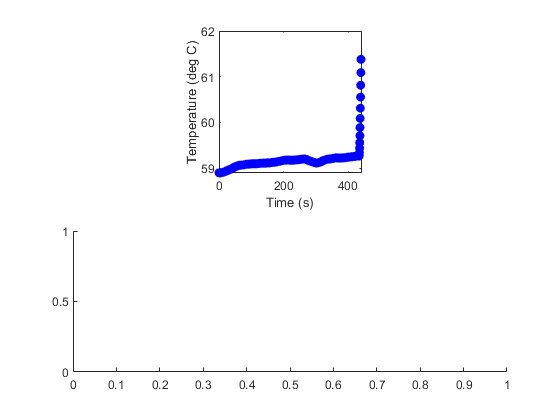

    figure(1);
    subplot(2,1,1)
    hold on
    plot(Ttosim,Z(1,:),'o','Color','blue','MarkerFaceColor','blue');
    xlabel('Time (s)')
    ylabel('Temperature (deg C)');
    axis square
    box on
    ax = gca;
    ax.Color = 'None';
    subplot(2,1,2)
    hold on    

    plot(t,z(2,:),'o','Color','blue','MarkerFaceColor','blue');

Unrecognized function or variable 't'.

    xlabel('Time (s)')
    ylabel('Voltage (V)');
    axis square
    box on
    ax = gca;
    ax.Color = 'None';    
    drawnow;
    xlim([-10,3700])

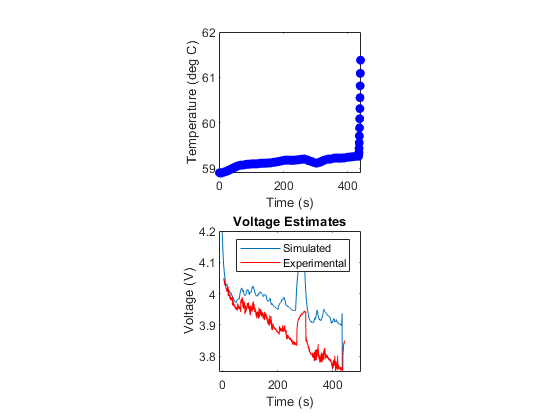

[Ttosim,~,~,Z] = battery.simulateToThreshold();
% figure(8)
plot(Ttosim,Z(2,:))
hold on
plot(5+ref_time,-0.05+ref_voltage,'-','Color','red');
hold off
title('Voltage Estimates');
xlabel('Time (s)');
ylabel('Voltage (V)');
legend('Simulated','Experimental');
xlim([-10 500])
ylim([3.75,4.2])
axis square
box on
ax = gca;
ax.Color = 'None';

% figure(7)
plot(Ttosim,Z(1,:))

% trueEOD = Ttosim(end);
endTemp = Z(1,end);
disp(' ')
disp('-------- Final Results --------')
disp(' ')
fprintf('Discharge time: %g s\nDischarge temperature: %g degC\n',Ttosim(end),endTemp);
fprintf('Ambient temperature: %g degC\n',battery.P.x0.Tb-273.15);
disp(' ')
disp('-------- End of final results --------')
disp(' ')

a = xlsread('C:\Users\mrmehta\OneDrive - NASA\linux_sync\NASA_John_SPARRCI\ARC_experiments\FORMATTED25_SINGLECELL.xlsx');

%%
plot(a(:,1),a(:,4)./6)
ylim([3.7,4.3])